# 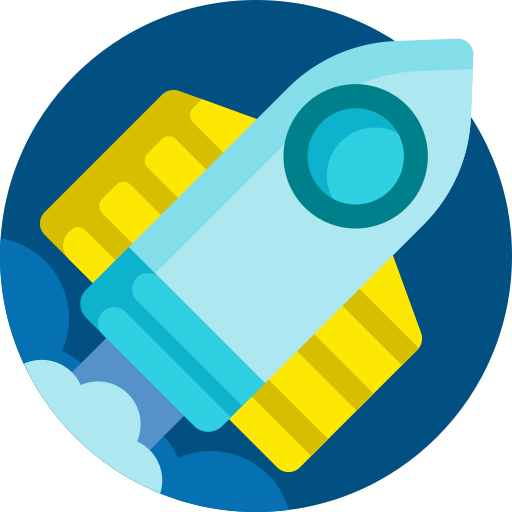

# **MEC3079S: Control Systems**

# Chapter 5 - Prediction of system response

## 5.1 Introduction

In this Chapter we will develop a deeper understanding between time-domain and Laplace-domain signals and systems, with the intention of predicting the system response of a modelled system. More specifically, if we have a model for $P(s)$, then how can we expect the output response $y(t)$ to behave for a set of define input signals $u(t)$.

As we introduced in **Chapter 1**, there are three key considerations in a control system, namely:

- Transient response — how quickly the output response settles after the system has been perturbed, and how oscillatory/erratic is the response during this period.

- Steady-state response — the final value that the response takes as time tends to infinity.

- Stability — whether the output response converges to a finite value, or diverges to $\pm$ infinity as time tends to infinity.

We will now begin to explore powerful Laplace domain techniques that can answer the above equations for any linear, time-invariant system.

## 5.2 Poles and zeros 

### 5.2.1 Definition

As shown in **Chapter 2**, any arbitrary transfer function, $P(s)$, can be written as a ratio of polynomials

$P(s)=\frac{a_0+a_1s+a_2s^2+...+a_ms^m}{b_0+b_1s+b_2s^2+...+b_ns^n}=\frac{N(s)}{D(s)}$,

where $\{a_i,b_i\}\in \mathbb{R}$ (the coefficients are real numbers) and $n\geq m$ (the denominator polynomial has equivalent or higher order than the numerator polynomial). Using factorization, $P(s)$ can be rewritten as a ratio of irreducible polynomials


$$\begin{array}{ll}
P(s) &= A_p \frac{ (s-z_1)(s-z_2) \ldots (s-z_m) }{ (s-p_1)(s-p_2) \ldots (s-p_n)}, \\
&= A_p\frac{\prod_{i=1}^m (s-z_i)}{\prod_{i=1}^n (s-p_i)},
\end{array}$$


where 

- the $z_i$ terms are the roots of the equation $N(s)=0$ (setting the numerator polynomial to zero), and 

- the $p_i$ terms are the roots of the equation $D(s)=0$ (setting the denominator polynomial to zero). 

Note that $z_i$ and $p_i$ are complex numbers in general: $\{z_i,p_i\}\in\mathbb{C}$. Importantly, a real number is a special type of complex number, just with the imaginary component set to zero ( e.g. $z_i=3=3+j0$). We can also think of $z_i$ as a value of $s$ that makes $P(s)=0$, namely 

$P(z_i)=0$.

Similarly, $p_i$ is a value of $s$ that makes $P(s)$ tend to infinity, namely

$P(p_i)=0$.

Importantly, this definition assumes that $z_i \neq p_k,~\forall i\neq k$. In other words, simplification of the factors above is not possible, hence the term *ratio of irreducible polynomials*. 

We will refer to the $z_i$ terms as the **zeros** of $P(s)$, and the $p_i$ terms as the **poles **of $P(s)$*. *As we will see later in this Chapter, the poles and zeros of our system actually tells us a lot of important information that we can use to determine performance and stability of our system. Note that the order (or degree) of the numerator polynomial, $N(s)$, is equal to the number of zeros of $P(s)$, and the order (or degree) of the denominator polynomial, $D(s)$, is equal to the number of poles of $P(s)$.

#### Example 1

*Determine the poles and zeros of *$P(s)=\frac{2}{s(s/5+1)}$.

The numerator polynomial is $0^\text{th}$-order, so there no zeros. 

We determine the poles of our system by setting the denominator polynomial equal to zero: $s(s/5+1)=s(s+5)=0$. The roots of this equation is $p_1=0$, and $p_2=-5$.

%Example 1
s = tf('s');
P = 2/( s*(s/5+1) );

[p,z] = pzmap(P) %determine the poles, p, and zeros,z, of P(s)


z =

  0×1 empty double column vector



#### Example 2

*Determine the poles and zeros of *$P(s)=\frac{2(0.5+s)}{s^2+2s+1}$.

We find the zeros by setting the numerator polynomial equal to zero: $2(0.5+s)=0$. The root of this equation is then $z=-0.5$. 

We determine the poles of our system by setting the denominator polynomial equal to zero: $s^2+2s+1=(s+1)^2=0$. The roots of this equation is $p_1=-1$, and $p_2=-1$.

%Example 2
s = tf('s');
P = 2*(0.5+s)/( s^2+2*s+1 );

[p,z] = pzmap(P) %determine the poles, p, and zeros,z, of P(s)

z = -0.5000

### 5.2.2 Relative degree

The relative degree of a transfer function is defined as the difference between the degree of the transfer function's denominator (equivalent to the number of poles of $P(s)$) and degree of the numerator (equivalent to the number of zeros of $P(s)$). Using the notation above, the relative degree is expressed as $n-m$. As will be explained later, we will only consider systems that have a degree of at least zero, which implies that $n\geq m$.

#### Strictly proper transfer function

A transfer function is classed **strictly proper** if the degree of the numerator is less than the degree of the denominators. This is the same as requiring that $n>m$, or that there are more poles in the transfer function than zeros.

For example, $F_1(s)=\frac{1}{2+s}$ is a strictly proper transfer function, as the numerator polynomial is of lower degree than that of the denominator polynomial, or equivalently, there are less zeros than poles — in this case, no zeros and one pole.

#### Biproper transfer function

A transfer function is classed as **biproper **if the degree of the numerator is equivalent to the degree of the denominator. This is the same as requiring that $n= m$, or that there are an equivalent number of poles and zeros in the transfer function.

For example, $F_2(s)=\frac{1+s}{2+s}$ is a proper transfer function, as both the numerator and denominator polynomials have the same degree, or equivalently, there is the same number of poles and zeros — in this case, one zero and one pole.

#### Proper transfer function

A transfer function is classed as **proper **if the degree of the numerator does not exceed the degree of the denominator. This is the same as requiring that $n\geq m$, or that there are at least as many poles in the transfer function as there are zeros. All systems we will consider are proper, which is a requirement for causality.

Both $F_1(s)$ and $F_2(s)$ are examples of proper transfer functions.

### 5.2.3 Pole-zero cancellation

Pole-zero cancellation occurs when a pole and zero are equivalent, which results in a cancellation of the two factors. 

#### Example 1

*Given *$P(s)=\frac{s+5}{s^2+10s+25}$*, determine the corresponding poles and zeros of the system.*

Using factorisation,  $P(s)=\frac{s+5}{s^2+10s+25}=\frac{s+5}{(s+5)(s+5)}=\frac{1}{(s+5)}$. 

Note that the system appeared to have one zero and two poles, but after simplification it turns out that there is only a single pole at $s=-5$.

s = tf('s');
P = (s+5)/(s^2+10*s+25)

P =
 
       s + 5
  ---------------
  s^2 + 10 s + 25
 
Continuous-time transfer function.
Model Properties



P = minreal(P) %the minreal function performs pole-zero cancellation if a cancellation exists.

P =
 
    1
  -----
  s + 5
 
Continuous-time transfer function.
Model Properties


[p,z] = pzmap(P)

p = -5


z =

  0×1 empty double column vector



#### Example 2

*Given *$P(s)=\frac{s+1}{s+2}$* and *$G(s)=\frac{s+3}{(s+1)(s+5)}$*, determine the poles and zeros of *$L(s)=P(s)G(s)$*.*

Multiplying the two transfer functions: $L(s)=P(s)G(s)=\frac{s+1}{s+2}\frac{s+3}{(s+1)(s+5)}=\frac{s+3}{(s+2)(s+5)}$.

Therefore, as a result of pole-zero cancellation, $L(s)$ has a zero at $s=-3$ and poles at $s=-2$ and $s=-5$.

s = tf('s');
P = (s+1)/(s+2);
G = (s+3)/(s+1)/(s+5);
L = P*G

L =
 
       s^2 + 4 s + 3
  -----------------------
  s^3 + 8 s^2 + 17 s + 10
 
Continuous-time transfer function.
Model Properties


L = minreal(L)

L =
 
      s + 3
  --------------
  s^2 + 7 s + 10
 
Continuous-time transfer function.
Model Properties


[p,z] = pzmap(L)

z = -3

### 5.2.4 The s-plane

The pole and zero locations in the complex plane infer a variety of characteristics of the system, such as rate of exponential growth/decay, frequency of oscillation, and stability (more on this later). We can explicitly define the $i^{th}$ **pole** of $P(s)$ as

$p_i=a_i+jb_i$,

where $a_i=\mathcal{R}\{p_i\}$ is the real component of pole $i$ and $b_i=\mathcal{I}\{p_i\}$ is the corresponding imaginary component. We can similarly define the $k^{th}$ **zero **of $P(s)$ as

$z_k=c_k+jd_k$.

Each pole and zero of $P(s)$ can be visualised on the complex plane, hereafter referred to as the **s-plane**, where poles are indicated with a $\times$ symbol, and zeros are shown with a $\bigcirc$ symbol, as seen below.

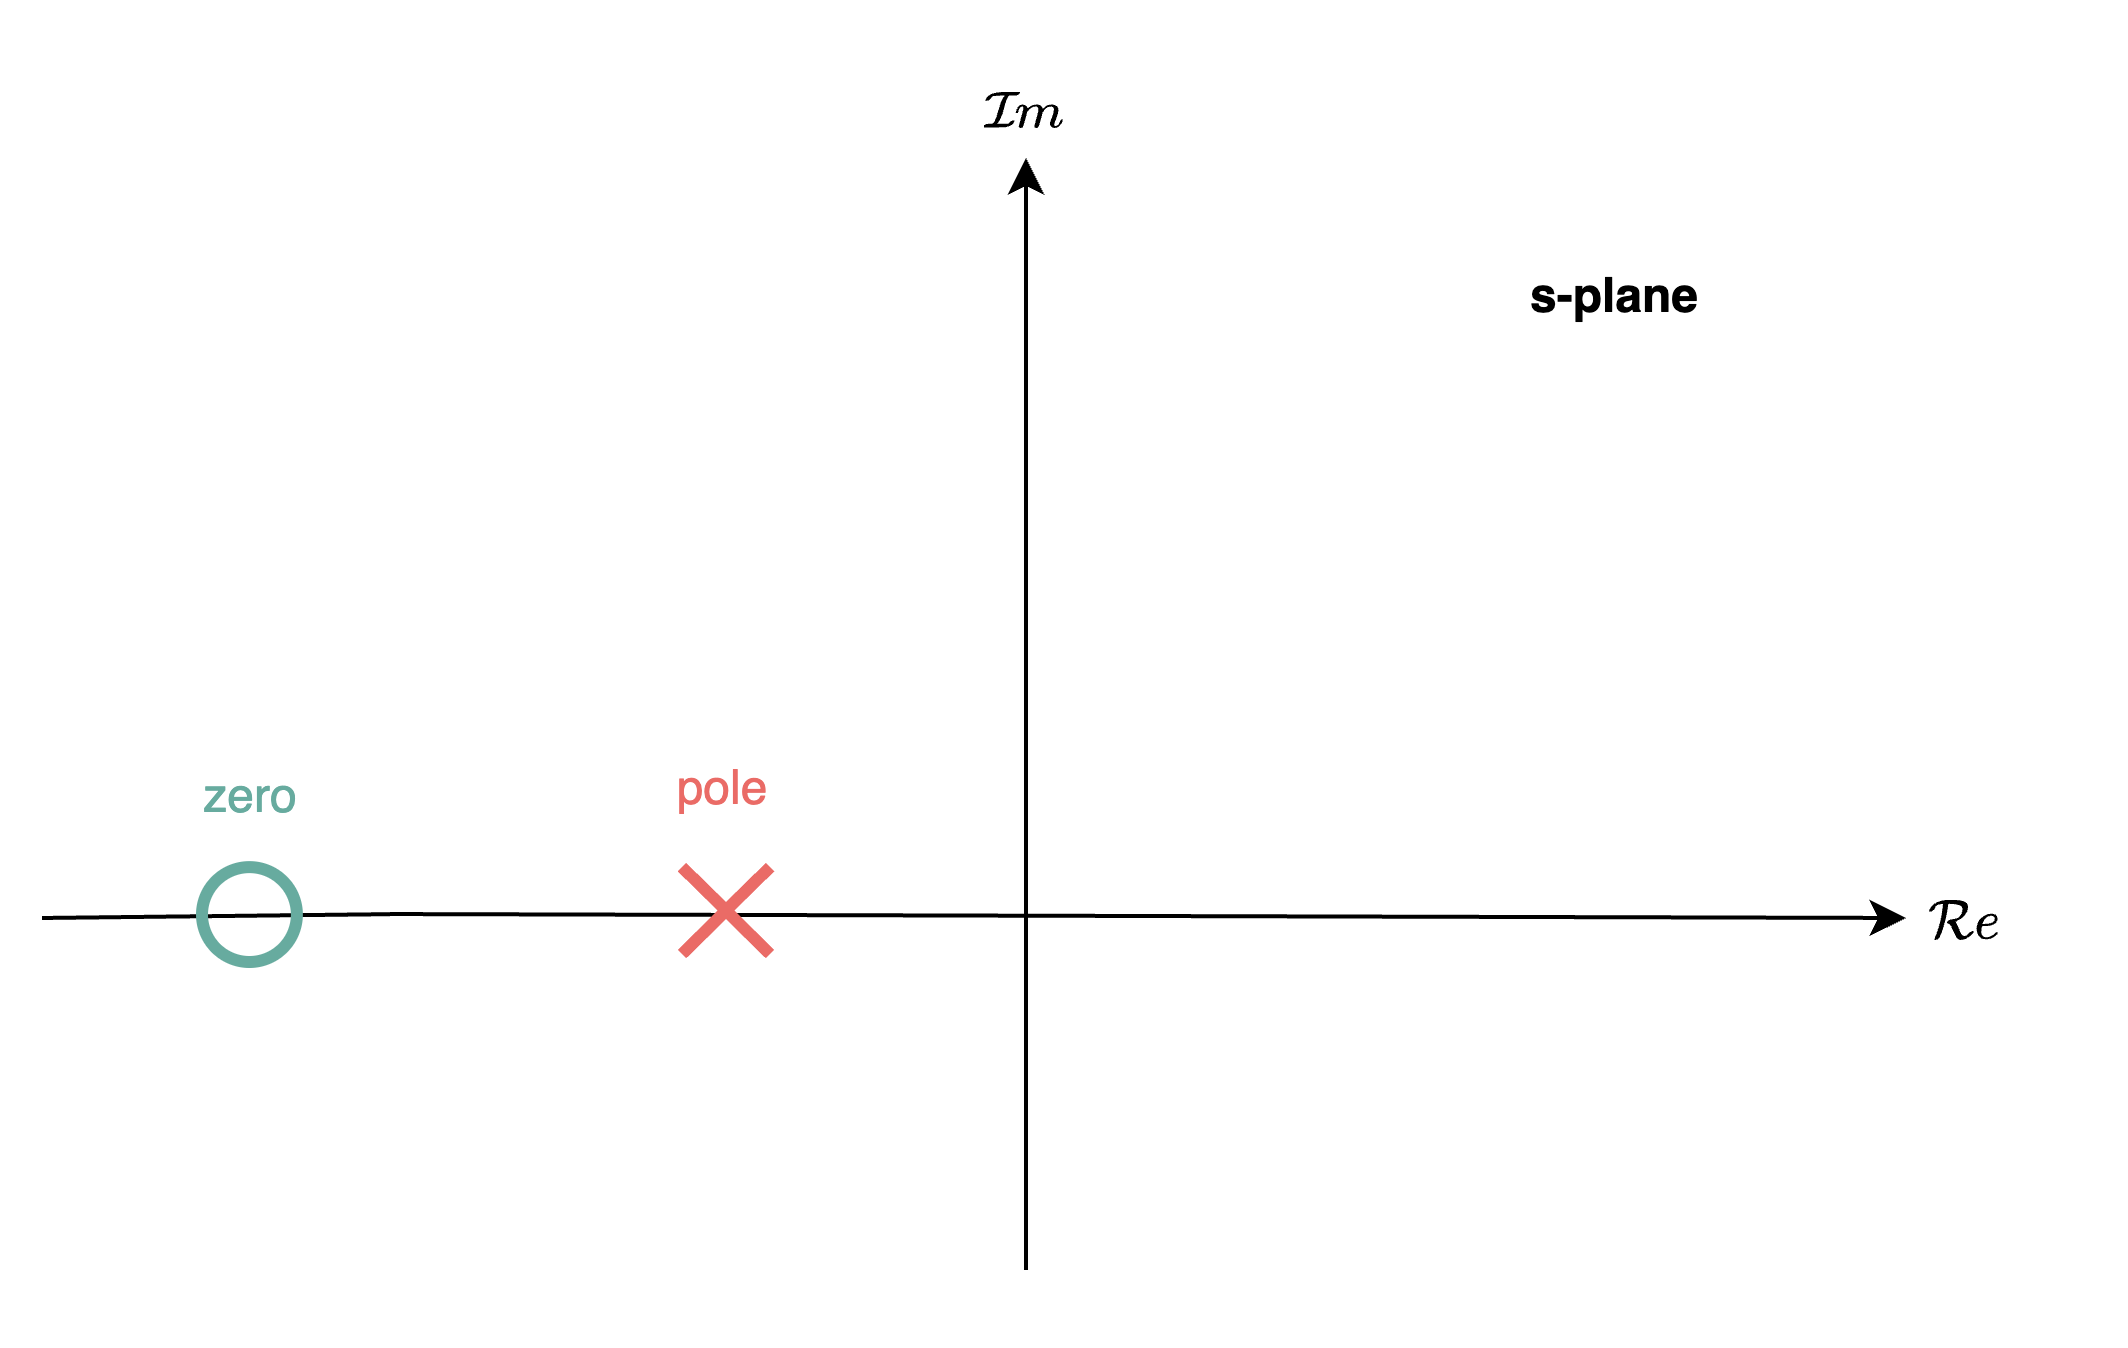

Recall that the $x$-axis of the complex plane indicates the *real* componet of a complex number, and the $y$-axis indicates the *imaginary* component.

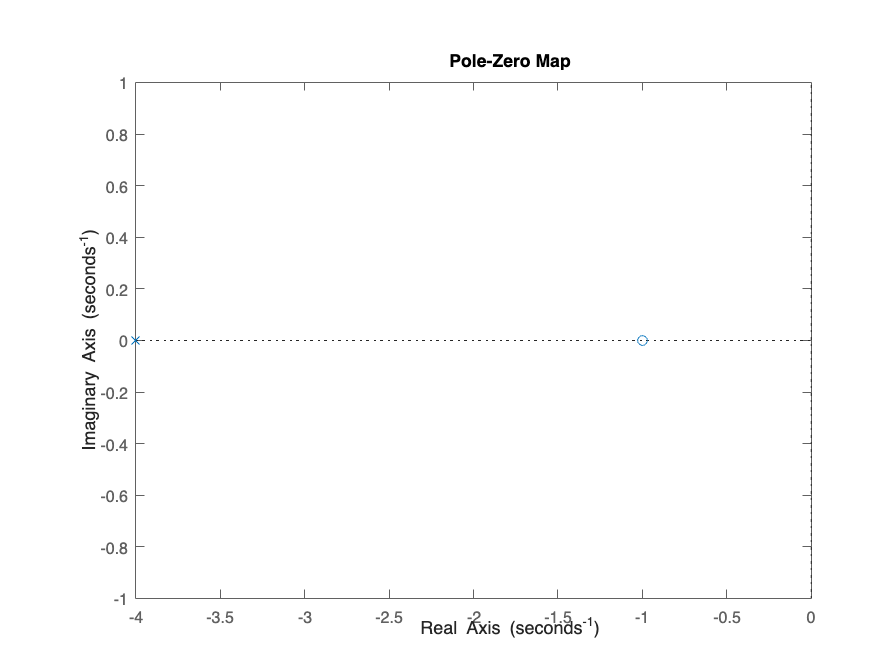

s = tf('s');

P = "(a+s)/(b+s)";
a = 1;
b = 4;

figure,clf,hold on
pzmap( eval(P) )


[p,z] = pzmap( eval(P) )

p = -4

z = -1

#### Open and closed left half-plane

We will refer to the left half of the s-plane, excluding the imaginary axis, as the **open left half-plane (OLHP)**. Specifically, the OLHP includes all complex numbers for which the real component of said complex number is *less* than zero. If we want to also include all complex numbers with real components equal to zero, we refer to this region as the **closed left half-plane (CLHP)**.

#### Open and closed right half-plane

Similar to the OLHP and CLHP, we refer to the right half of the s-plane, excluding the imaginary axis, as the **open right half-plane (ORHP)**. Specifically, the ORHP includes all complex numbers for which the real component is *greater* than zero. If we want to also include all complex numbers with real components equal to zero, we refer to this region as the **closed right half-plane (CRHP)**.

Based on the definitions above, there is no intersection between the OLHP and ORHP, but the intersection of the CLHP and CRHP is described by the imaginary axis. We will use these definitions to make sense of stability in future sections.

## 5.3 Partial fraction expansion 

We saw in **Chapter 2** that we can make use of the inverse Laplace transform to determine $y(t)$ given a $Y(s)$ that is listed in the Laplace transform table. However, in many cases the signal that we want to apply the inverse Laplace to may not be represented in our table. To circumvent this issue we can make use of **partial fraction expansion** to reduce an unknown signal (or system) into a sum of signals that are individually recognisable in the transform table. Based on the linearity property of the (inverse) Laplace transform, we then simply take the inverse Laplace transform of each individual signal (or subsystem) and then sum the result.

We will also soon see that our pole and zero locations play a key role in how our system will respond to input perturbations.

### 5.3.1 Transfer functions with distinct poles

Recall that we can describe a transfer function as a ratio of polynomials

$P(s)=\frac{a_0+a_1s+a_2s^2+...+a_ms^m}{b_0+b_1s+b_2s^2+...+b_ns^n}=\frac{N(s)}{D(s)}$,

and assuming that we are only dealing with **distinct poles** ($p_i\neq p_k,~\forall i\neq k$), we can use the partial fraction expansion to represent $P(s)$ as a sum of transfer functions, namely


$$\begin{array}{ll}
P(s) &=  A_p\frac{\prod_{i=1}^m (s-z_i)}{\prod_{i=1}^n (s-p_i)}, \\
&= \sum_{i=1}^{n}\frac{r_i}{s-p_i}+k,
\end{array}$$


where 


$$r_i = \lim_{s\rightarrow p_i} (s-p_i)P(s),$$


and 

$k=\lim_{s\rightarrow \infty}P(s)=\left\{
        \begin{array}{ll}
           A_p, &  m=n, \\
           0, & m< n. \\
        \end{array}
    \right.$.

Note that $r_i, p_i \in \mathbb{C}$ in general, whereas $k \in \mathbb{R}$. Note that if $P(s)$ is strictly proper ($m<n$), then $k$ will equal zero.

We will only consider the system response of *strictly proper* systems (where $n<m$, implying that there are more poles than zeros) in this course (although the extension to proper systems is trivial). It follows that $k=0$, which simplifies the partial fraction expansion of $P(s)$ to


$$\begin{array}{ll}
P(s) 
&= \sum_{i=1}^{n}\frac{r_i}{s-p_i},
\end{array}$$


where 

$r_i = \lim_{s\rightarrow p_i} (s-p_i)P(s)$.

#### Example

*Determine the partial fraction expansion of *$P(s)=\frac{5}{s+s^2/10}$*.*

Based on the formulation above we can express $P(s)$ as


$$\begin{array}{ll}
P(s) 
&=  \frac{5}{s(1+s/10)}, \\
&=  \frac{50}{s(10+s)}, \\
&= \frac{r_1}{s+10}+\frac{r_2}{s}.
\end{array}$$


We then determine $r_1$ and $r_2$ using

$r_1 = \lim_{s\rightarrow -10} (s+10)P(s) = \lim_{s\rightarrow -10} \frac{50}{s} = -5$,

$r_2 = \lim_{s\rightarrow 0} sP(s) = \lim_{s\rightarrow 0} \frac{50}{10+s} = 5$,

which results in


$$\begin{array}{ll}
P(s) 
&= \frac{-5}{s+10}+\frac{5}{s},
\end{array}$$


We can use the [`residue`](https://www.mathworks.com/help/matlab/ref/residue.html) function in `MATLAB` to find $r_1$, $r_2$, $p_1$, $p_2$.

P = 5/( s+s^2/10 );
[num,den] = tfdata(P,'v');

[r,p,~] = residue(num,den) %find residuals (r1,r2) and poles (p1,p2) of P(s)

### 5.3.2 Transfer functions with repeated poles

Consider the system

$P(s)=\frac{a_0+a_1s+a_2s^2+...+a_ms^m}{b_0+b_1s+b_2s^2+...+b_ns^n}=\frac{N(s)}{D(s)}$,

where $x \in \mathbb{N}_{>1}$ poles are repeated, namely

$P(s)=\frac{N(s)}{(s-p_1)^x(s-p_{x+1})...(s-p_n)}$.

We can then use partial fraction expansion to express strictly proper $P(s)$ as


$$\begin{array}{ll}
P(s)
&=  A_p\frac{\prod_{i=1}^m (s-z_i)}{(s-p_1)^x\prod_{i=x+1}^n (s-p_i)}, \\
&= \sum_{i=1}^{x}\frac{r_i}{(s-p_1)^i} + \sum_{i=x+1}^{n}\frac{r_i}{s-p_i},
\end{array}$$


where

$r_i=\lim_{s\rightarrow p_1}\frac{1}{(i-1)!}\frac{d^{i-1}P^*(s)}{ds^{i-1}$,

and

$P^*(s)=P(s)(s-p_1)^x$.

Note that $r_i, p_i \in \mathbb{C}$ in general. The partial fraction expansion of a transfer function with repeated poles is definitely more involved, but we will often only deal with systems that have up to $x=2$ repeated poles.

#### Example

*Determine the partial fraction expansion of *$P(s)=\frac{1}{s^3+s^2}$*.*

Based on the formulation above we can express $P(s)$ as


$$\begin{array}{ll}
P(s) 
&=  \frac{1}{s^3+s^2}, \\
&=  \frac{1}{s^2(s+1)}, \\
&= \frac{r_1}{s^2}+\frac{r_2}{s}+\frac{r_3}{s+1},
\end{array}$$


We then determine $r_1$,$r_2$, and $r_3$ using

$r_1 = \lim_{s\rightarrow 0} s^2P(s) = \lim_{s\rightarrow 0} \frac{1}{s+1} = 1$,

$r_2 = \lim_{s\rightarrow 0}\frac{d}{ds}s^2P(s)=\lim_{s\rightarrow 0} -\frac{1}{(s+1)^2} = -1$,

$r_3 = \frac{1}{2}\lim_{s\rightarrow 0}\frac{d^2}{ds^2}s^2P(s)=\frac{1}{2}\lim_{s\rightarrow 0} \frac{2}{(s+1)^3} = 1$,

which results in


$$\begin{array}{ll}
P(s) 
&=  \frac{1}{s^2(s+1)}, \\
&= \frac{1}{s^2}-\frac{1}{s}+\frac{1}{s+1},
\end{array}$$


P = 1/( s^2*(s+1) );
[num,den] = tfdata(P,'v');

[r,p,~] = residue(num,den) %find residuals (r3,r2,r1) and poles (p3,p2,p1) of P(s)

## 5.4 Impulse response

### 5.4.1 Definition

The **impulse response** of a system is the output generated from an impulse input (commonly also referred to as the dirac delta function) of the form


$$u(t)=\delta(t) =\left\{
        \begin{array}{ll}
           \infty, &  t = 0, \\
           0, & t \neq 0. \\
        \end{array}
    \right.$$


This is also commonly referred to as the *natural response*, with a graphical representation shown below.

       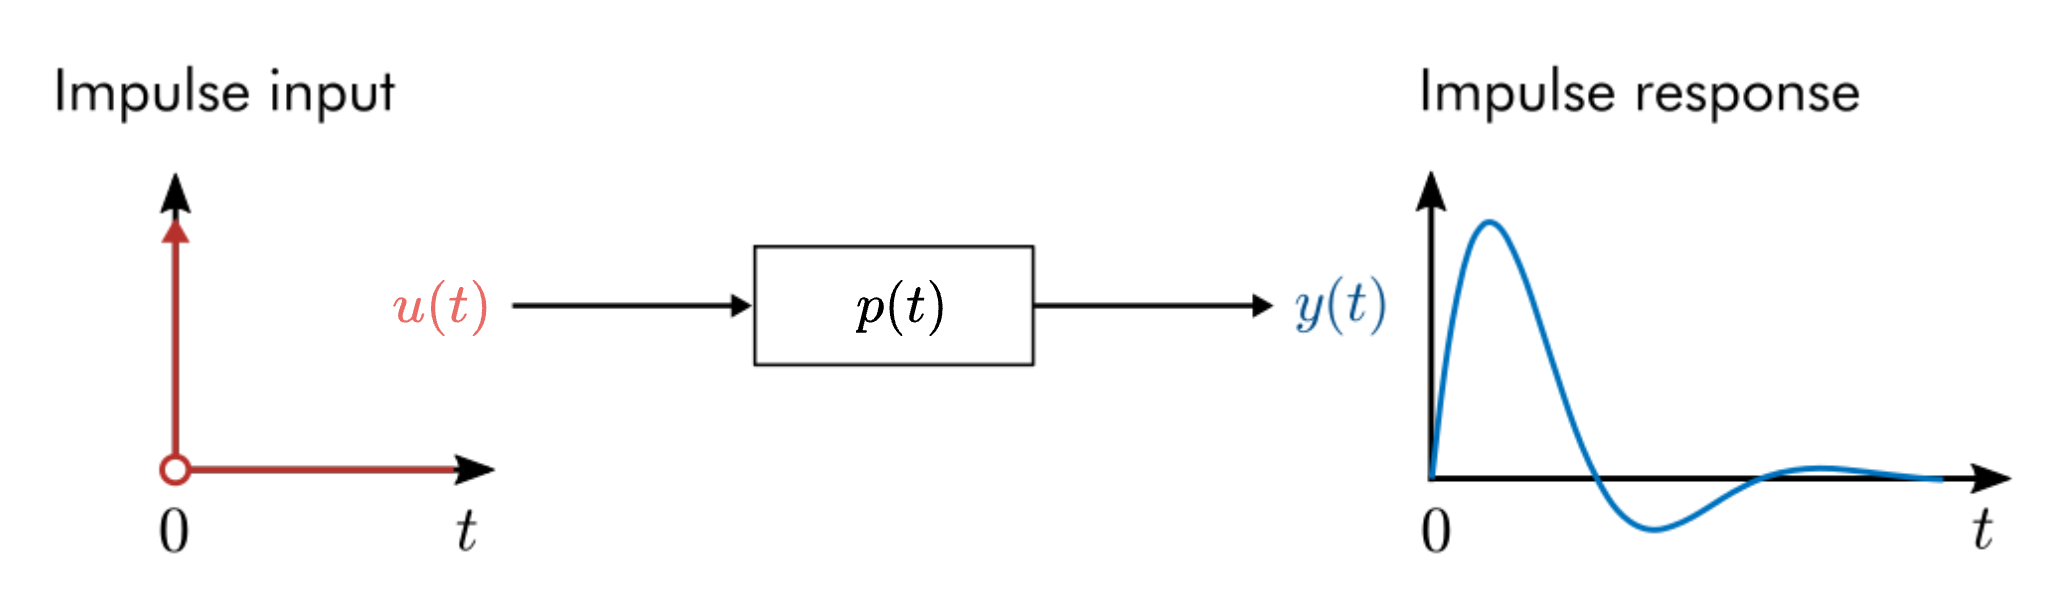

The appeal of using an impulse input signal is that the Laplace transform of $u(t)=\delta(t)$ is $U(s)=1$, based on


$$\begin{array}{ll}
U(s) &= \int_{0}^{\infty} u(t) e^{-st} \ dt, \\
 &= \int_0^\infty \delta(t) e^{-st}dt, \\
&=1.
\end{array}$$


This means that the corresponding impulse response (the response of the system output to an inpulse input) will be 

$Y(s)=P(s)U(s)=P(s)$. 

Under these conditions the partial fraction expansion of $Y(s)=P(s)$ follows from the previous sections depending on whether there are repeated roots in the denominator or not, namely


$$\left.
\begin{array}{lll}
\text{No repeated poles } (p_i\neq p_k): \quad& Y(s) = \sum_{i=1}^{n}\frac{r_i}{s-p_i},
 \quad & r_i = \lim_{s\rightarrow p_i} (s-p_i)P(s)
\\
x \text{ repeated poles } (p_1=p_2=...p_x) \quad&  Y(s)=\sum_{i=1}^{x}\frac{r_i}{(s-p_1)^i} + \sum_{i=x+1}^{n}\frac{r_i}{s-p_i}, \quad & r_i=\lim_{s\rightarrow p_1}\frac{1}{(i-1)!}\frac{d^{i-1}P(s)(s-p_1)^x}{ds^{i-1}
\end{array}
\right.
$$


What we should notice here is that the impulse response will be made up of a sum of terms, whereby each pole of $P(s)$ contributes a term to the response of $Y(s)$.

### 5.4.2 Impulse response of a transfer function with real, distinct poles

In the case that each pole of strictly proper $P(s)$ is distinct, we have shown that the impulse response will be

$Y(s) = \sum_{i=1}^{n}\frac{r_i}{s-p_i}$,

where

$r_i = \lim_{s\rightarrow p_i} (s-p_i)P(s)$,

and $p_i$ is the $i^\text{th}$ pole of our system. Recall from our Laplace transform table that an exponential response in the time domain is described in the Laplace domain by

$\mathcal{L}\{ae^{-bt}\} = \frac{a}{s+b}$.

Based on this transform, $Y(s)$ above can be inverse Laplace transformed to determine $y(t)$ as

$\begin{array}{ll}
y(t) &=   \sum_{i=1}^{n}{r_i}e^{p_it}
\end{array}$.

The result above means that when an impulse input is applied to a strictly proper system with distinct poles, the resulting impulse response will be a sum of (real-valued or complex) exponentials. If all poles of $P(s)$ are **real**, namely

$p_i=a_i+j0=a_i,~\forall i$,

it follows that $r_i, p_i \in \mathbb{R}$. The time-domain impulse response of a strictly proper system is then made up of a sum of *real-valued *exponentials, 

$y(t)=\sum_{i=1}^{n}{r_i}e^{p_it}=\sum_{i=1}^{n}{r_i}e^{a_it}$.

Based on our understanding of the exponential function for real-vaued $r_i, a_i $, we know that


$$\lim_{t\rightarrow \infty}r_ie^{a_it}=r_i\lim_{t\rightarrow \infty}e^{a_it}=\left\{
        \begin{array}{ll}
           0, &  a_i<0, \\
           r_i, & a_i=0, \\
\infty, & a_i>0.
        \end{array}
    \right.$$


In other words, if $a_i<0$, then the $i^\text{th}$ exponential term will tend to zero over time, whereas if $a_i>0$, then the $i^\text{th}$ exponential term, and by extension, $y(t)$, will grow without bound and tend to infinity over time. This means that if $a_i>0$ for *any one pole* in $P(s)$, then $y(t)$ will run off to infinity. On the other hand, if $a_i<0,~\forall i$, then the impulse response, $y(t)$, will tend to zero, as all the exponential terms that make up $y(t)$ tend to zero over time. The special case of $a_i=0$ simply means that there is no exponential response for pole $i$, and the particular response is instead a step signal with value $r_i$.

We can easily visualise the real-valued poles in the s-plane, as shown below. The above equation suggests that pole $i$ lying in the open left half-plane (OLHP), implying $a_i<0$, will result in the corresponding $y_i(t)={r_i}e^{a_it}$ term tending to zero with time..

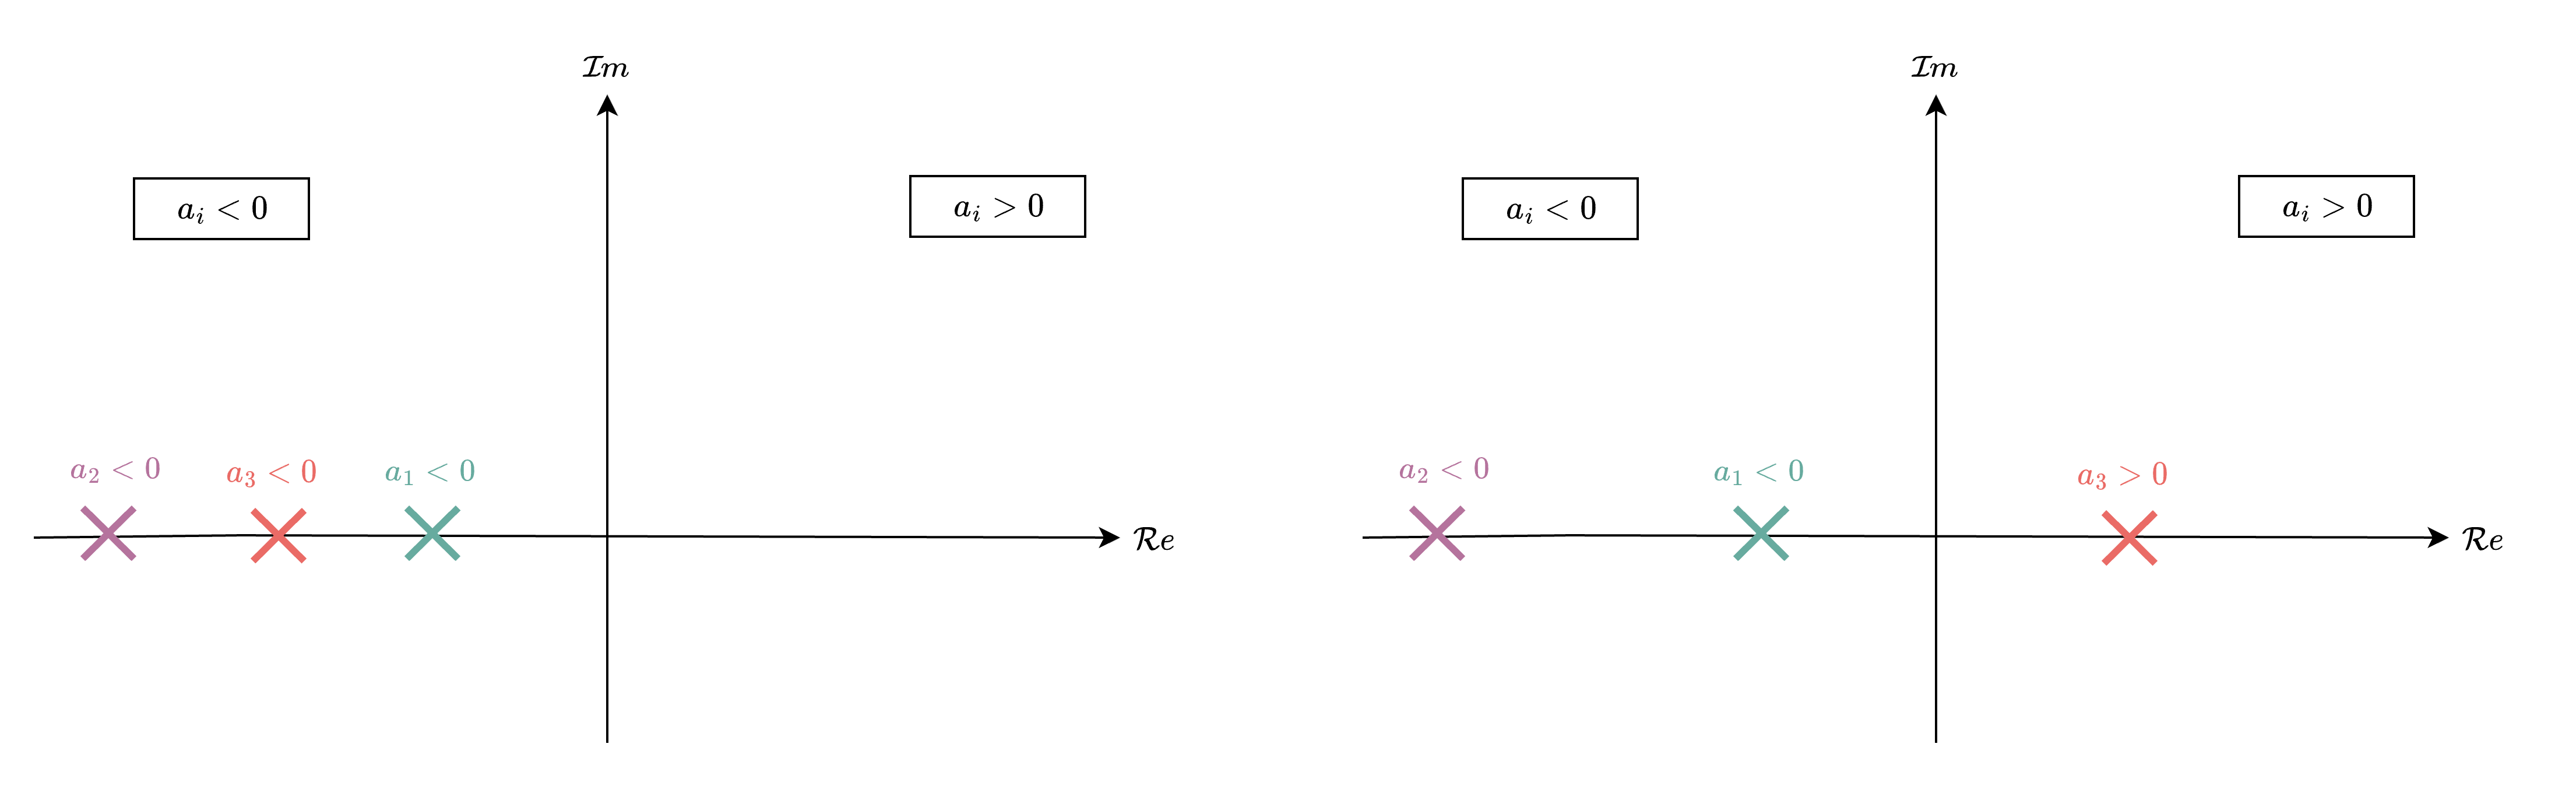

Therefore, if *all* poles of the system lie in the OLHP, then 


$$y(t)=\sum_{i=1}^{n}{y_i}(t)=\sum_{i=1}^{n}{r_i}e^{a_it}$$
 

will converge to zero, namely 

$\lim_{t\rightarrow \infty} y(t) = 0$.

The left figure above is an example of such a case. In the converse, if any *one* pole lies in the open right half-plane (ORHP), as shown in the right figure above, then the system will have a divergent impulse response (even though the other two poles are in the OLHP).

#### **Example**

*Given that the input is an impulse, *$u(t)=\delta(t)$*, and *$P(s)=\frac{1}{(s+a)(s+b)}$*, where *$a,b \in \mathbb{R},~a\neq b$*, determine *$y(t)$*.*

The output signal follows as $Y(s)=P(s)U(s)=\frac{1}{(s+a)(s+b)}$, with the poles of $P(s)$ at $p_1=-a$ and $p_2=-b$. Using partial fraction expansion on $Y(s)$, we get


$$Y(s)=\frac{1}{(s+a)(s+b)}=\frac{r_1}{s+a}+\frac{r_2}{s+b}.$$


Using our residual formula,


$$r_1= \lim_{s\rightarrow -a} (s+a)Y(s)=\lim_{s\rightarrow -a} \frac{1}{s+b}=\frac{1}{b-a},$$


$r_2= \lim_{s\rightarrow -b} (s+b)Y(s)=\lim_{s\rightarrow -b} \frac{1}{s+a}=-\frac{1}{b-a}$.

Therefore

$Y(s)=\frac{1}{(s+a)(s+b)}=\frac{\frac{1}{b-a}}{s+a}-\frac{\frac{1}{b-a}}{s+b}$.

We can confirm that the partial fraction expansion is correct by resolving the right-hand side term above to be a single term, or by using the `residue` function as before. Finally, we convert $Y(s)$ to $y(t)$ using the Laplace transform table and the *linearity* property:


$$\begin{array}{ll}
y(t) &= \mathcal{L}^{-1}\{Y(s)\},\\
&= \frac{1}{b-a}e^{-at}-\frac{1}{b-a}e^{-bt}.\\
\end{array}$$


The time-domain response of $y(t)$ as well as each individual exponential response is shown using the code below, where $a$ and $b$ can be adjusted. 

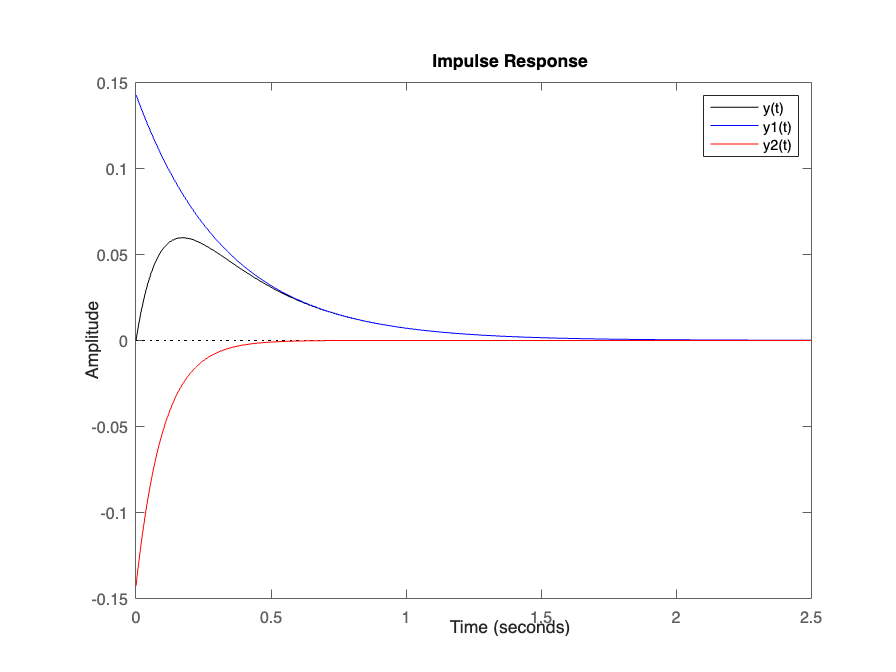

%Example
s = tf('s');

a = 3; %p1 = -a
b = 10; %p2 = -b
P = 1/(s+a)/(s+b);

P1 = 1/(b-a)/(s+a);
P2 = -1/(b-a)/(s+b);

figure,hold on
impulse(P,'k')
impulse(P1,'b')
impulse(P2,'r')
legend('y(t)','y1(t)','y2(t)')

Playing around with different $a$ and $b$ values, you should notice the following: 

- for $a,b>0$, the output converges to zero as $t\rightarrow \infty$, as the poles of $P(s)$ are defined as $(p_1,p_2)=(-a,-b)$.

- for $a=b=0$, the output is a ramp response: $y(t)=t$, based on $Y(s)=\frac{1}{(s+a)(s+b)}=\frac{1}{s^2}$,

- for $a<0$ **or** $b<0$, the output signal grows without bound, as one of the exponential terms goes tends to infinity over time,

- increasing the magnitude of $a$ and $b$ increases the rate of response of $y(t)$. In other words, how quickly the response tends to zero or infinity, depending on the sign of $a$ and $b$.

Remembering that $a$ and $b$ are the locations of our poles, it appears that the pole location has a deterministic affect on how $y(t)$ behaves. The code below plots the positions of the poles.

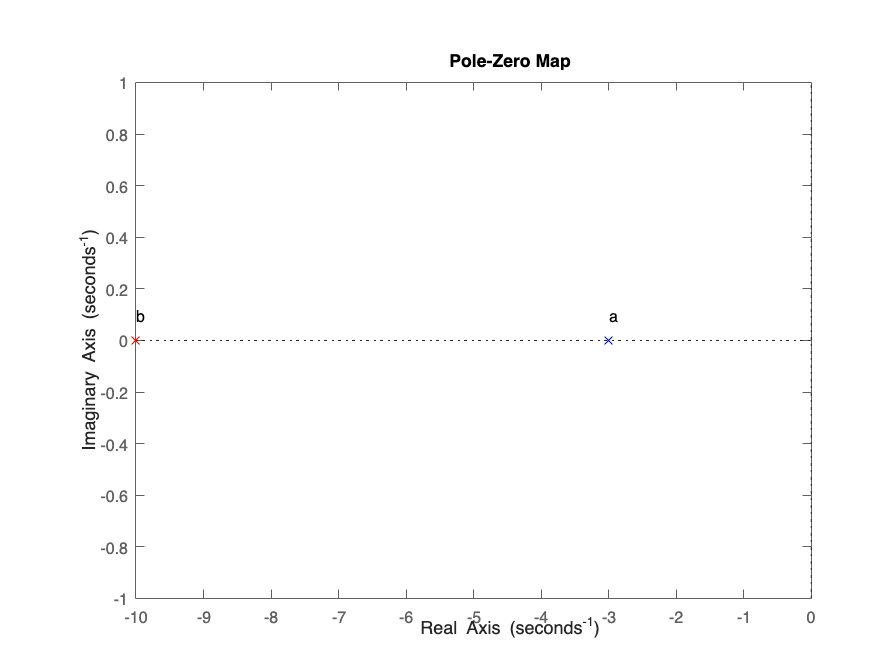

figure, hold on
pzmap(P)
plot(-a,0,'xb')
plot(-b,0,'xr')
text(-a,.1,'a')
text(-b,.1,'b')

### 5.4.3 Impulse response of a transfer function with real, repeated poles

In the case that there are $x$ **repeated** poles in a strictly proper system, we have already shown that


$$\begin{array}{ll}
Y(s)
&= P(s)\\
&=  A_p\frac{\prod_{i=1}^m (s-z_i)}{(s-p_1)^x\prod_{i=x+1}^n (s-p_i)}, \\
&= \sum_{i=1}^{x}\frac{r_i}{(s-p_1)^i} + \sum_{i=x+1}^{n}\frac{r_i}{s-p_i}
\end{array}$$


If all poles are real, namely $p_i \in \mathbb{R},~\forall i$, the second term from the above equation of $\sum_{i=x+1}^{n}\frac{r_i}{s-p_i}$ will behave as in the previous section, resulting in a sum of exponential responses, $\sum_{i=x+1}^{n}{r_i}e^{a_it}$ , whereby the convergent/divergent behaviour is determined by whether $a_i$ is less/greater than zero. 

Given that all poles of $Y(s)=P(s)$ are known to be real ($p_i=a_i+0j$), the first term of $Y(s)$,

$\sum_{i=1}^{x}\frac{r_i}{(s-p_1)^i}=\sum_{i=1}^{x}\frac{r_i}{(s-a_1)^i}$ ,

is equivalent to a sum of $i^\text{th}$-order functions, $\frac{r_i}{s^i}$, with a frequency shift of $a_i$, based on the frequency shift property

$e^{at} f(t) = \mathcal{L}^{-1}\{  F(s-a) \}$.

For example, if $x=2$, then 

$\sum_{i=1}^{2}\frac{r_i}{(s-a_1)^i}=\frac{r_1}{s-a_1}+\frac{r_2}{(s-a_1)^2}$,

and the inverse Laplace transform follows as


$$\begin{array}{rl}
\mathcal{L}^{-1}\{ \sum_{i=1}^{2}\frac{r_i}{(s-a_1)^i}\}
&= \mathcal{L}^{-1}\{\frac{r_1}{s-a_1}\}+\mathcal{L}^{-1}\{\frac{r_2}{(s-a_1)^2}\},\\
&= e^{a_1t}\mathcal{L}^{-1}\{\frac{r_1}{s}\}+e^{a_1t}\mathcal{L}^{-1}\{\frac{r_2}{s^2}\},\\
&= r_1e^{a_1t}+r_2te^{a_1t},\\
&=e^{a_1t}\left(r_1+r_2t\right).\\
\end{array}$$


As before, if $a_1<0$, then the above equation will tend to zero based on the exponential decay, and if $a_1>0$ then the equation will tend to infinity. Interestingly, if $a_1=0$, then the above term reduces to $r_1+r_2t$, which is a ramp-like signal that runs off to infinity with $t$.

In general, the inverse Laplace transform of $\sum_{i=1}^{x}\frac{r_i}{(s-a_1)^i}$ follows as

$\mathcal{L}^{-1}\{ \sum_{i=1}^{x}\frac{r_i}{(s-a_1)^i}\}=\sum_{i=1}^{x}r_ie^{a_1t}\frac{t^{i-1}}{(i-1)!$ ,

with the same convergent requirement of $a_1<0$.

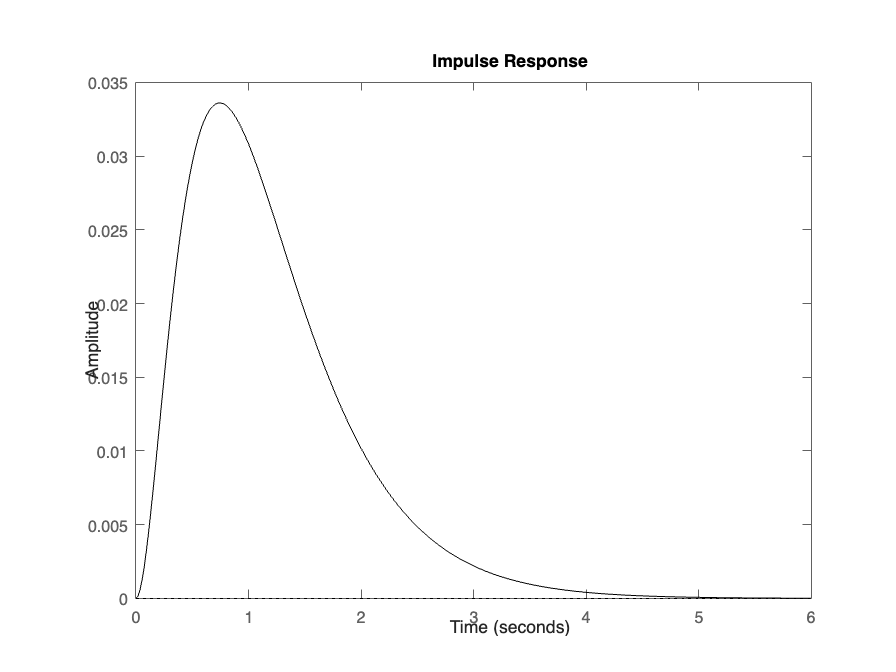

s = tf('s');

a = 2; %repeated pole of p1=p2 = -a
b = 5; %p3 = -b
P = 1/(s+a)^2/(s+b);

[num,den] = tfdata(P,'v');
[r,p,~] = residue(num,den)

figure,hold on
impulse(P,'k')

### 5.4.4 Impulse response of a transfer function with complex, distinct poles

**Section 5.4.2** considered the case when the poles of $P(s)$ are real and distinct. However, systems can also contain **complex** poles. Consider the case where the impulse response is given by


$$\begin{array}{ll}
Y(s)
&= P(s)\\
&=  A_p\frac{\prod_{i=1}^m (s-z_i)}{\prod_{i=1}^n (s-p_i)}, \\
&= \sum_{i=1}^{2}\frac{r_i}{(s-p_i)} + \sum_{i=3}^{n}\frac{r_i}{s-p_i}
\end{array}$$


where $p_1,p_2 \in \mathbb{C}$. In other words, two of the $n$ poles are complex:

$p_i=a_i+jb_i,~~b_i\neq0 ,~~\forall i\in\{1,2\}$.

It follows that $r_1,r_2 \in \mathbb{C}$, based on  

$r_i = \lim_{s\rightarrow p_i} (s-p_i)P(s)$.

The second term from of $\sum_{i=3}^{n}\frac{r_i}{s-p_i}$ will behave as in the previous section, resulting in a sum of real-valued exponential responses, $\sum_{i=3}^{n}{r_i}e^{a_it}$ , whereby the convergent/divergent behaviour is determined by whether $a_i$ is less/greater than zero. 

Complex poles always come in conjugate pairs, namely $p_2=p_1^*$, where $p_1=a_1+jb_1$ and $p_2=a_1-jb_1$. Taking the inverse Laplace transform of $\sum_{i=1}^{2}\frac{r_i}{s-p_i}$, this has the structure of

$\begin{array}{ll}
 \sum_{i=1}^{2}{r_i}e^{p_it}=r_1e^{(a_1+jb_1)t}+r_1^*e^{(a_1-jb_1)t
\end{array}$, 

where it can be shown that $r_2=r_1^*$. Defining $r_1=v_1+jw_1$, we can write the above equation as


$$\begin{array}{ll}
\sum_{i=1}^{2}{r_i}e^{p_it} &=r_1e^{(a_1+jb_1)t}+r_1^*e^{(a_1-jb_1)t} \\
&=(v_1+jw_1)e^{(a_1+jb_1)t}+(v_1-jw_1)e^{(a_1-jb_1)t \\
&= e^{a_1t}\left((v_1+jw_1)e^{jb_1t}+(v_1-jw_1)e^{-jb_1t}\right)
\end{array}$$


Using Euler's formula of $e^{jx}=\cos(x)+j\sin(x)$, we can reduce the above equation to


$$\begin{array}{ll}
\sum_{i=1}^{2}{r_i}e^{p_it} &=
e^{a_1t}\left((v_1+jw_1)(\cos(b_1t)+j\sin(b_1t))+(v_1-jw_1)(\cos(b_1t)-j\sin(b_1t))\right),
 \\
&= 2e^{a_1t}\left( v_1\cos(b_1t)-w_1\sin(b_1t)\right).

\end{array}$$


This result can be further reduced, using the trigonomometric identity of $\cos{\alpha+\beta}=\cos{\alpha}\cos{\beta}-\sin{\alpha}\sin{\beta}$, to 


$$\begin{array}{ll}
\sum_{i=1}^{2}{r_i}e^{p_it} 
&= 2e^{a_1t}\left( v_1\cos(b_1t)-w_1\sin(b_1t)\right),\\
&= 2\sqrt{v_1^2+w_1^2}e^{a_1t}\cos(b_1t-\phi),

\end{array}$$


where $\phi=-\tan^{-1} \frac{w_1}{v_1}}$. Notably, the imaginary component of the complex pole, $b_1=\mathcal{I}\{p_1\}$, determines the frequency of the cosinusoid, whereas the the real component of the complex pole, $a_1=\mathcal{R}\{p_1\}$, determines the exponential behaviour of the signal.

The code below shows that the result above is equivalent to using `MATLAB`'s `impulse` function when the system has two complex conjugate poles, namely $P(s)=\frac{1}{(s+p_1)(s+p_1^*)}$.

%Example
s = tf('s');

a = 3; %real component of complex conjugate pole pair
b = 5; %imaginary component of complex conjugate pole pair
p1 = a+1i*b;
p2 = p1';  %determine complex conjugate of p1 

P = 1/(s+p1)/(s+p2)

P =
 
        1
  --------------
  s^2 + 6 s + 34
 
Continuous-time transfer function.
Model Properties


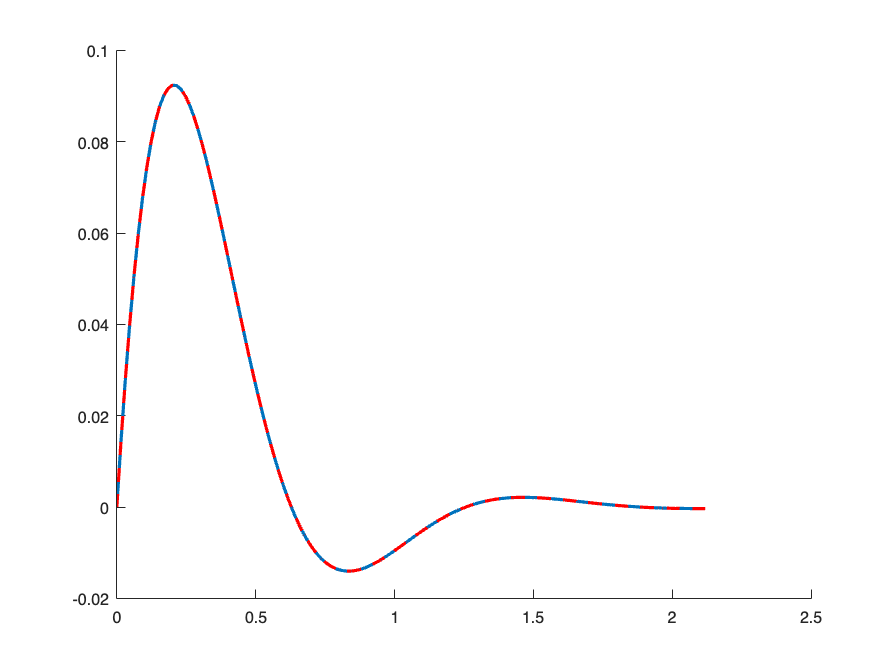

[y,t] = impulse(P);

[num,den] = tfdata(P,'v');
[r,p,~] = residue(num,den);
v = real( r(1) );
w = imag( r(1) );

phi = -atan( w/v );
a = real( p(1) );
b = imag( p(1) );
y_ = 2*sqrt(v^2+w^2)*exp(a*t).*cos(b*t-phi);

figure, hold on
plot(t,y,lineWidth=2)
plot(t,y_,'r--',lineWidth=2)

The cosinusoidal response from the complex conjugate pole pair of $2\sqrt{v_1^2+w_1^2}e^{a_1t}\cos(b_1t-\phi)
$ is bounded in amplitude by $2\sqrt{v_1^2+w_1^2}e^{a_1t}$ and will either 

- exhibit a damped cosinusoidal response (the cosine will shrink over time),

- maintain an undamped response (the cosine amplitude will remain unchanged over time), or 

- exhibit an unstable response (where the cosine amplitude increases over time).

We can use our understanding of the exponential limit below to determine how the amplitude of the cosine will change with time based on


$$\lim_{t\rightarrow \infty}2\sqrt{v_1^2+w_1^2}e^{a_1t}=2\sqrt{v_1^2+w_1^2}\lim_{t\rightarrow \infty}e^{a_1t}=\left\{
        \begin{array}{ll}
           0, &  a_1<0, \\
           2\sqrt{v_1^2+w_1^2}, & a_1=0, \\
\infty, & a_1>0.
        \end{array}
    \right.$$


So $\sum_{i=1}^{2}{r_i}e^{p_it}=2\sqrt{v_1^2+w_1^2}e^{a_1t}\cos(b_1t-\phi)
$ will tend to zero over time if $a_1<0$ (case 1 above). However, if $a_1>0$, then the amplitude of the cosine function will grow with time (case 2). Finally, if $a_1=0$, the cosine will continue for all time, with a constant amplitude of $2\sqrt{v_1^2+w_1^2}$ (case 3). 

We can therefore deduce that the component of an impulse response of a system with a complex conjugate pole pair will converge to zero if $a_1<0$, which is the same convergent condition for our system with strictly real poles. If all the system poles are plotted in the s-plane (including real-valued poles), we can easily determine whether the impulse response will converge to zero or diverge based on their locations in the s-plane. Specifically, if all poles are located in the open left half-plane (as shown in the left figure below), the impulse response will converge to zero, whereas if any one pole resides in the open right half-plane (as shown in the right figure below), then the response will diverge to infinity.

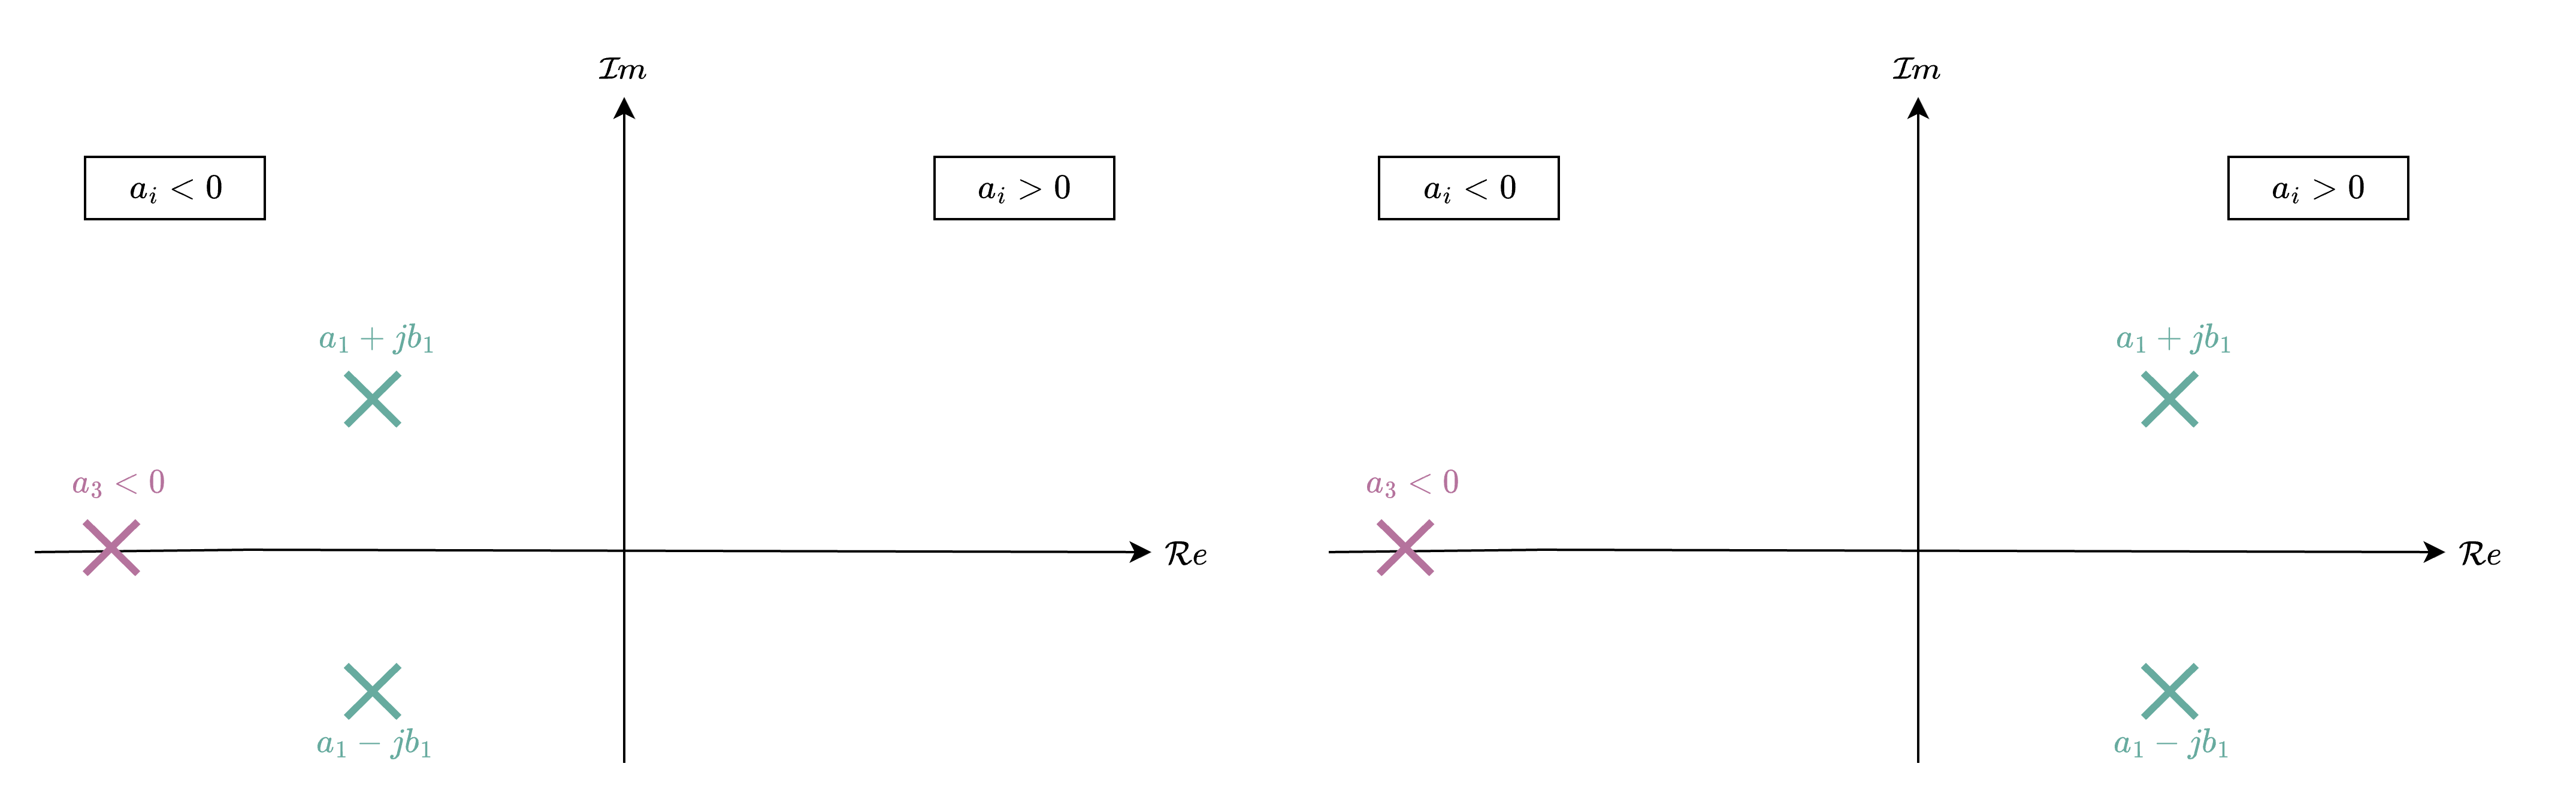

#### Arbitrary number of complex conjugate pair of poles

The derivation above can be extended to an number of compex conjugate pole pairs by considering the contribution of each complex conjugate pair seperately, namely

$\sum_{i=1}^{b}{r_i}e^{p_it}=\left(r_1e^{p_1t}+r_1^*e^{p_1*t}\right)+\left(r_3e^{p_3t}+r_3^*e^{p_3*t}\right)+...+\left(r_{b-1}e^{p_{b-1}t}+r_{b-1}^*e^{p_{b-1}*t}\right)$,

and this result in a sum of cosinusoids of the form


$$\begin{array}{ll}
\sum_{i=1}^{b}{r_i}e^{p_it} 
&= \sum_{i=1}^{b-1}2\sqrt{v_{2i-1}^2+w_{2i-1}^2}e^{a_{2i-1}t}\cos(b_{2i-1}t-\phi),

\end{array}$$


The signal above is guaranteed to converge to zero if $a_i<0,~\forall i$, and will result in an unstable output if $a_i>0$ for any one pole.

#### Issue with impulse inputs

Impulse inputs of $u(t)=\delta(t)$ are mathematically appealing input signals, based on the fact that $U(s)=\mathcal{L}\{\delta(t)\}=1$. We effectively get to set the output signal equal to that of the system under consideration. However, the problem with impulse inputs is that we cannot physically manifest a signal that is infinitely large for an infinitesimally small period of time (based on the mathematical definition). Approximations of an impulse signal do exist, such as a pulse function, which has a finite magnitude and duration, but the Laplace transfer function will no longer be equal to one.

An alternative approach is to use so-called *step input signals*, which is detailed in the following section.

## 5.5 Step response

### 5.5.1 Definition

The **unit** **step input** is a very useful signal that can be used to assess the stability and performance of a system. Importantly, it gets around the issue of the impulse response not being realisable in general. It is formally defined as the **Heaviside step function**, $\sigma(t)$, in many mathematical textbooks. In essence, it is a signal that has a value of zero for all negative time ($t<0$) and 1 everywhere else ($t\geq 0$), namely 


$$\sigma(t)=\left\{
        \begin{array}{ll}
           1, &  t \geq 0, \\
           0, & t < 0. \\
        \end{array}
    \right.$$


The output generated from a unit step input is known as the unit **step response**, with an example of the time-domain response shown below. Think of the step response as the system's response to a sustained, instantaneous constant perturbation. 

    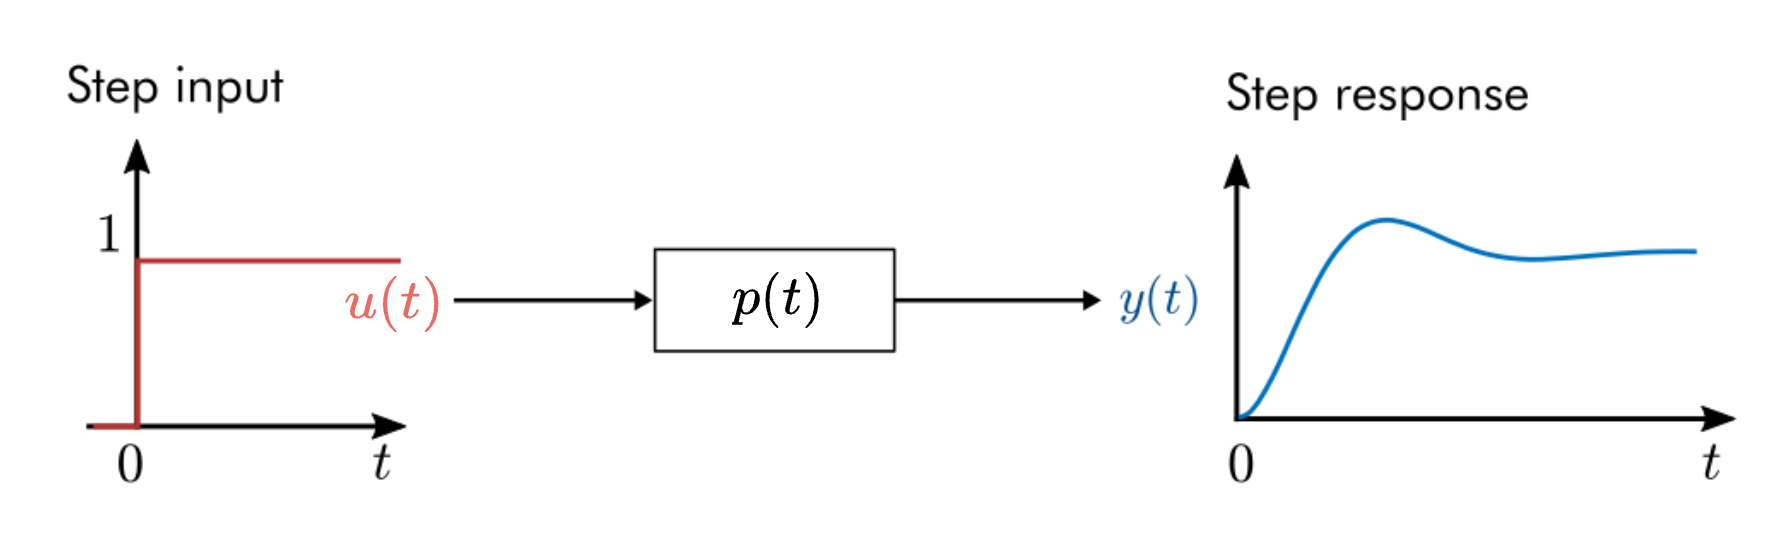

We have already defined the unit step function to be 


$$\begin{array}{ll}
U(s) &= \int_{0}^{\infty} \sigma(t) e^{-st} \ dt, \\
 &= \int_0^\infty e^{-st}dt, \\
&=\frac{1}{s}.
\end{array}$$


Note that the *unit* step function is defined when the step input has a magnitude of one. Using our previous formulation of $Y(s)=P(s)U(s)$, the unit step response can be described as

$Y(s)=P(s)U(s)=P(s)\frac{1}{s}$. 

### 5.5.2 Step response of a transfer function with real, distinct poles

Recall that a strictly proper plant with real, distinct poles is described as


$$\begin{array}{ll}
P(s) &=  A_p\frac{\prod_{i=1}^m (s-z_i)}{\prod_{i=1}^n (s-p_i)}, \\
&= \sum_{i=1}^{n}\frac{r_i}{s-p_i},
\end{array}$$


where 

$r_i = \lim_{s\rightarrow p_i} (s-p_i)P(s)$.

The corresponding step response follows as


$$\begin{array}{ll}
Y(s) 
&= P(s)\frac{1}{s},\\
&=  A_p\frac{\prod_{i=1}^m (s-z_i)}{s\prod_{i=1}^n (s-p_i)}, \\
&= \sum_{i=1}^{n}\frac{r_i}{s-p_i}+\frac{r_{n+1}}{s}.
\end{array}$$


The first term is a result of the *natural response* of the system (taking the same form as the impulse response but with different $r_i$ values), and the second term is a result of the *forced response* of the system (from the step input).

The corresponding time-domain response is found by applying the inverse Laplace transform, which yields


$$\begin{array}{ll}
y(t) 
&= \mathcal{L}^{-1}\{\sum_{i=1}^{n}\frac{r_i}{s-p_i}\}+\mathcal{L}^{-1}\{\frac{r_{n+1}}{s}\},\\
&=   \sum_{i=1}^{n}{r_i}e^{a_it}+r_{n+1},
\end{array}$$


where $p_i=a_i+0j$. Reflecting on the equation above, if all poles lie in the OLHP ($a_i<0,~\forall i$), then $y(t)$ will converge to $r_{n+1}$ as time tends to infinity, namely

$\lim_{t\rightarrow \infty} y(t) = r_{n+1}$.

How quickly the step response tends to $r_{n+1}$ is also dependant on the magnitude of $a_i$ values. Conversely, if any one pole lies in the ORHP ($\exists ~a_i>0$) then $y(t)$ will tend to infinity. Notice that this is exactly the same condition that we found when dealing with the impulse response.

#### **Example**

*Given that the input signal is a unit step, *$u(t)=\sigma(t)$*, and *$P(s)=\frac{k}{s+a}$*, where *$a,k\in \mathbb{R}$*, determine *$y(t)$*.*

The output signal follows as 

$Y(s)=P(s)U(s)=\frac{k}{s+a}\frac{1}{s}=\frac{r_1}{s+a}+\frac{r_2}{s}$.  

Using our residual formula,


$$r_1= \lim_{s\rightarrow -a} (s+a)Y(s)=\lim_{s\rightarrow -a} \frac{k}{s}=-\frac{k}{a},$$


$r_2= \lim_{s\rightarrow 0} sY(s)=\lim_{s\rightarrow 0} \frac{k}{s+a}=\frac{k}{a}$,

and $Y(s)$ follows as

$Y(s)=\frac{-k/a}{s+a}+\frac{k/a}{s}$.  

Converting $Y(s)$ to $y(t)$ using the Laplace transform table, we get


$$\begin{array}{ll}
y(t) &= \mathcal{L}^{-1}\{\frac{-k/a}{s+a}\}+\mathcal{L}^{-1}\{\frac{k/a}{s}\},\\
      &=-\frac{k}{a}e^{-at}+\frac{k}{a},\\
      &=\frac{k}{a}\left(1-e^{-at}).
\end{array}$$


The time-domain response of $y(t)$ is shown below, where $k$ and $a$ can be adjusted. 

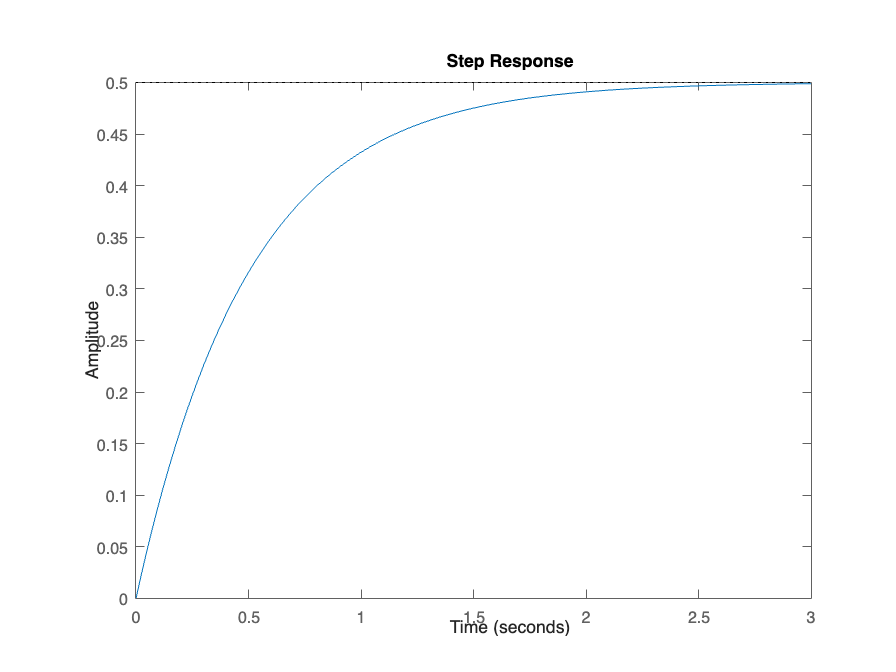

%Example
s = tf('s');
k = 1;
a = 2; % pole at p=-a
P = k/(s+a);
figure,clf
step(P)

### 5.5.3 Step response of a transfer function with real, repeated poles

Recall that if there are $x$ repeated poles in a strictly proper system, we can expand $P(s)$ as


$$\begin{array}{ll}
P(s)
&=  A_p\frac{\prod_{i=1}^m (s-z_i)}{(s-p_1)^x\prod_{i=x+1}^n (s-p_i)}, \\
&= \sum_{i=1}^{x}\frac{r_i}{(s-p_1)^i} + \sum_{i=x+1}^{n}\frac{r_i}{s-p_i}.
\end{array}$$


In the case of the step response we have $Y(s)=P(s)\frac{1}{s}$, which implies that


$$\begin{array}{ll}
Y(s)
&=  A_p\frac{\prod_{i=1}^m (s-z_i)}{s(s-p_1)^x\prod_{i=x+1}^n (s-p_i)}, \\
&= \sum_{i=1}^{x}\frac{r_i}{(s-p_1)^i} + \sum_{i=x+1}^{n}\frac{r_i}{s-p_i}+\frac{r_{n+1}}{s}.
\end{array}$$


Importantly, this assumes that $s=0$ is a distinct pole (we will cover this scenario in more detail in a later section). As in the case of the impulse response, the first term above, when inverse Laplace transformed, will reduce to a sum of $i^\text{th}$-order functions with exponential coefficients, where each term will decay to zero if $a_i<0$ . After applying the inverse Laplace transform, the second term above will reduce to a sum of exponential functions, where the $a_i$ values will dictate whether the individual responses converge to zero or run off to infinity. The third term in $Y(s)$ simply corresponds to $r_{n+1}$ in the time domain.

The result above means that we can again make use of our "impulse response" understanding when determining whether $y(t)$ will be convergent or divergent, with the main difference being that $\lim_{t\rightarrow\infty} y(t)=r_{n+1}$when $a_i<0,~\forall i$.

### 5.5.4 Step response of a transfer function with complex, distinct poles

In the case that $P(s)$ has two complex conjugate poles, $p_1$ and $p_2$, we can decompose our plant as before using


$$\begin{array}{ll}
P(s)
&=  A_p\frac{\prod_{i=1}^m (s-z_i)}{\prod_{i=1}^n (s-p_i)}, \\
&= \sum_{i=1}^{2}\frac{r_i}{(s-p_i)} + \sum_{i=3}^{n}\frac{r_i}{s-p_i},
\end{array}$$


where $p_1,p_2 \in \mathbb{C}$. When $U(s)$ is a unit step input, the output response, $Y(s)=P(s)U(s)$, follows as 


$$\begin{array}{ll}
Y(s)
&= P(s)\frac{1}{s},\\
&=  A_p\frac{\prod_{i=1}^m (s-z_i)}{s\prod_{i=1}^n (s-p_i)}, \\
&= \sum_{i=1}^{2}\frac{r_i}{(s-p_i)} + \sum_{i=3}^{n}\frac{r_i}{s-p_i}+\frac{r_{n+1}}{s},
\end{array}$$


We can therefore make use of our "impulse response" understanding to predict the behaviour of the first two terms in the equation above. When applying the inverse Laplace transform, the first term will result in an exponential cosinusoid, the second term will be a sum of exponential functions, and the third term will be a constant, namely


$$y(t)=2\sqrt{v_1^2+w_1^2}e^{a_1t}\cos(b_1t-\phi)+ \sum_{i=3}^{n}{r_i}e^{a_it}+r_{n+1},
$$


where $a_i=\mathcal{R}\{p_i\}$, $r_1=v_1+w_1$, and $\phi=-\tan^{-1} \frac{w_1}{v_1}}$.

The code below demonstrates the step response for a system of the form $P(s)=\frac{1}{(s+p_1)(s+p_1^*)}$.

s = tf('s');

a = -6; %real component of complex conjugate pole pair
b = 5; %imaginary component of complex conjugate pole pair

p1 = a+1i*b;
p2 = p1';  %determine complex conjugate of p1 

P = 1/(s-p1)/(s-p2)

P =
 
         1
  ---------------
  s^2 + 12 s + 61
 
Continuous-time transfer function.
Model Properties


[y,t] = step(P);

[num,den] = tfdata(P/s,'v');
[r,~,~] = residue(num,den)

r =   -0.0082 + 0.0098i
  -0.0082 - 0.0098i
   0.0164 + 0.0000i


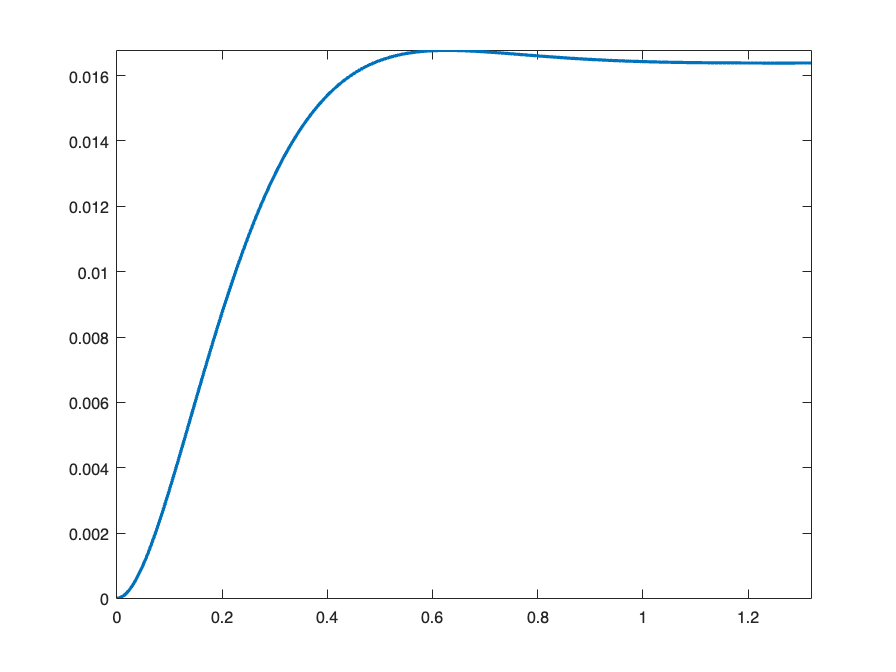


figure
plot(t,y,lineWidth=2)
axis tight

#### Example

*Given that the input is a unit step, *$u(t)=\sigma(t)$*, and *$P(s)=\frac{1}{s^2+2s+2},$* determine *$y(t)$*.*

The output signal follows as $Y(s)=P(s)U(s)=\frac{1}{s^2+2s+2}\frac{1}{s}$. Using partial fraction expansion on $Y(s)$, we get

$Y(s)=\frac{1}{(s^2+2s+2)s}=\frac{r_1}{s+1+j}+\frac{r_2}{s+1-j}+\frac{r_3}{s}$.

As expected, the two plant poles are complex conjugates: $1+j=(1-j)^*$.

Using our residual formulas from before, we get 


$$r_1= \lim_{s\rightarrow -1-j} (s+1+j)Y(s)=\lim_{s\rightarrow -1-j} \frac{1}{(s+1-j)s}=-0.25-j0.25,$$



$$r_2= \lim_{s\rightarrow -1+j} (s+1-j)Y(s)=\lim_{s\rightarrow -1+j} \frac{1}{(s+1+j)s}=-0.25+j0.25,$$



$$r_3= \lim_{s\rightarrow 0} sY(s)=\lim_{s\rightarrow 0} \frac{1}{(s+1+j)(s+1-j)}=0.5,$$


The output response follows as


$$Y(s)=\frac{1}{(s^2+2s+2)s}=\frac{-0.25-j0.25}{s+1+j}+\frac{0.25+j0.25}{s+1-j}+\frac{0.5}{s}.$$


The time-domain output response is determined by taking the inverse Laplace transform


$$\begin{array}{ll}
y(t) &= \mathcal{L}^{-1}\{Y(s)\},\\
&= \mathcal{L}^{-1}\{\frac{-0.25-j0.25}{s+1+j}+\frac{0.25+j0.25}{s+1-j}\}+\mathcal{L}^{-1}\{\frac{0.5}{s}\},\\
&= \mathcal{L}^{-1}\{\frac{-0.25-j0.25}{s+1+j}+\frac{0.25+j0.25}{s+1-j}\}+0.5,
\end{array}$$


which will take the form of


$$y(t)=2\sqrt{v_1^2+w_1^2}e^{a_1t}\cos(b_1t-\phi)+0.5,
$$


where $a_i=\mathcal{R}\{p_i\}$, $r_1=v_1+w_1$, and $\phi=-\tan^{-1} \frac{w_1}{v_1}}$. Using this formulation, we determine $y(t)$ as


$$y(t)=0.7071e^{-t}\cos(t+2.36)+0.5,
$$


where $a_1=-1$, $b_1=1$, $v_1=-0.25$, $w_1=-0.25$, and $\phi=-2.36$ rad. The time-domain step response of $y(t)$ is generated using the code below.

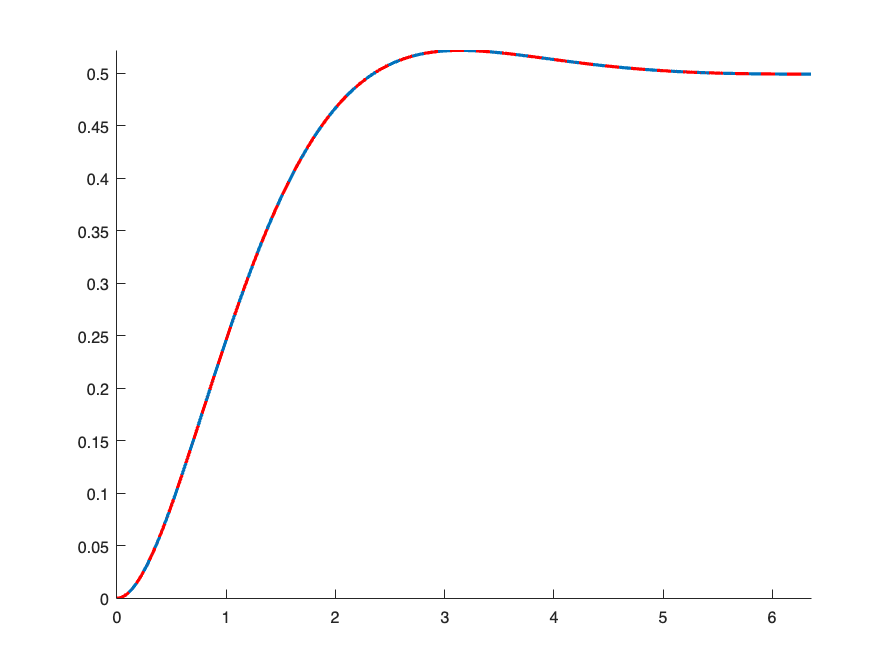

%Example
s = tf('s');
P = 1/(s^2+2*s+2);
[y,t] = step(P);    %step response of P(s) using MATLAB function

a = -1; 
b = 1;
v = -0.25;
w = 0.25;
phi = -atan2(w,v);
y_ = 2*sqrt(v^2+w^2)*exp(a*t).*cos(b*t-phi)+0.5;    %step response of P(s) based on mathematical formulation.

figure,hold on
plot(t,y,lineWidth=2)
plot(t,y_,'--r',lineWidth=2)
axis tight

## 5.6 Response to an arbitrary input

The impulse and step input are two examples of the input signals that are used, but in the general case, the input can take any physically realisable form (more on this later).

        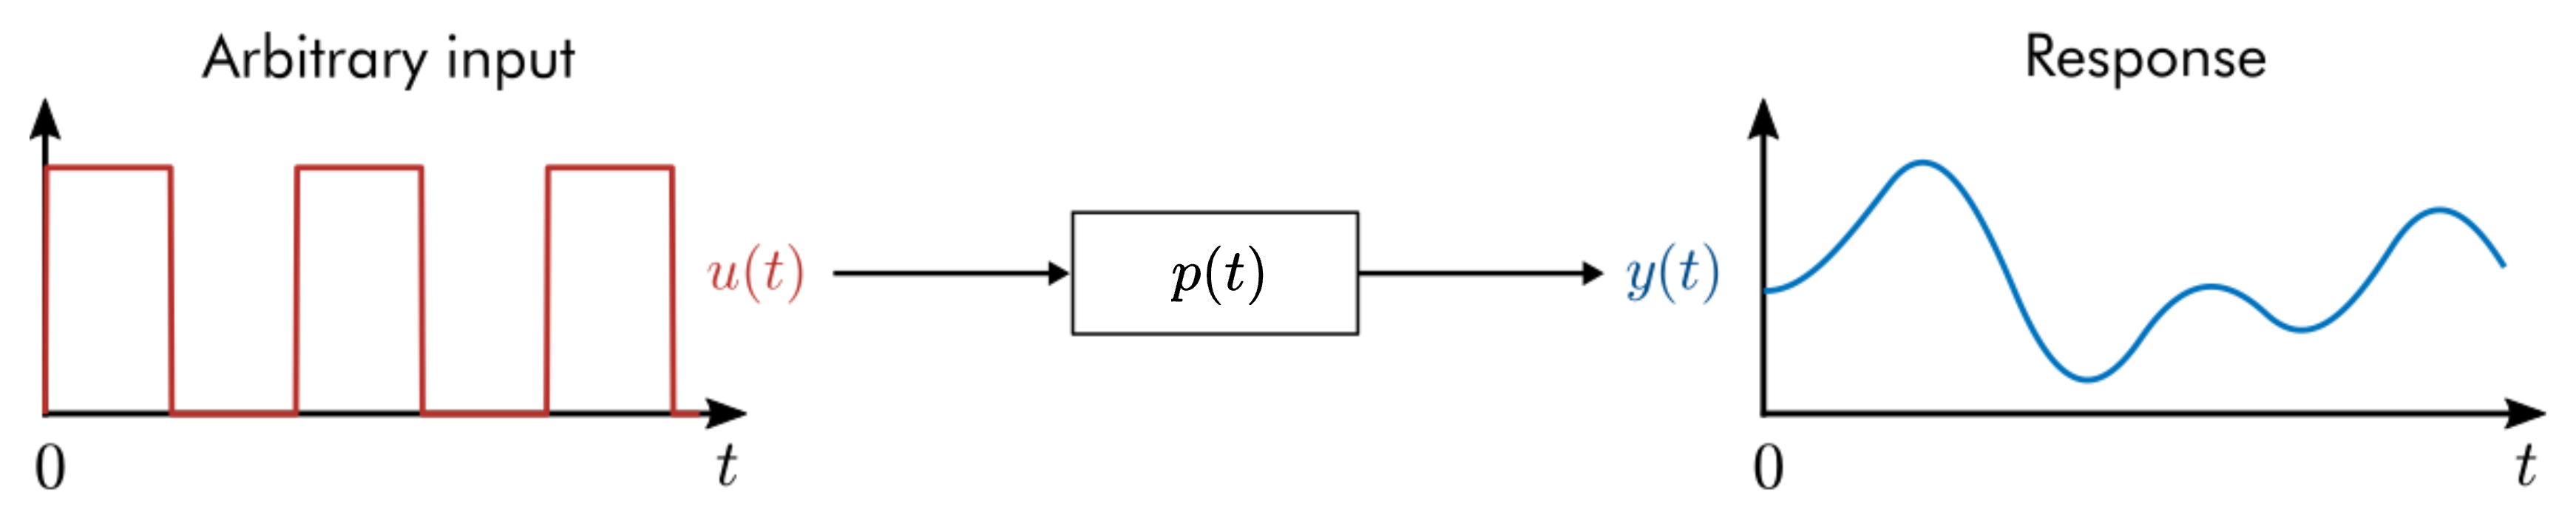

An arbitrary input signal, $U(s)$, can also be described as a ratio of factorised polynomials in a similar manner to that of $P(s)$: 


$$\begin{array}{ll}
U(s) &=  A_u\frac{\prod_{i=m+1}^{m+a} (s-{z}_i)}{\prod_{i=n+1}^{n+b} (s-p_i)}. \\
\end{array}$$


If $U(s)$is applied to system $P(s)$, and assuming for sake of simplicity that all poles in $Y(s)$ are distinct, then using $Y(s)=P(s)U(s)$, the output signal follows as


$$\begin{array}{ll}
Y(s) &=  A_p A_u\frac{\prod_{i=1}^m (s-z_i)}{\prod_{i=1}^n (s-p_i)}\frac{\prod_{i=m+1}^{m+a} (s-{z}_i)}{\prod_{i=n+1}^{n+b} (s-p_i)}, \\
&= A_p A_u\frac{\prod_{i=1}^{m+a} (s-{z}_i)}{\prod_{i=1}^{n+b} (s-p_i)}, \\
&= \sum_{i=1}^{n}\frac{r_i}{s-p_i}+\sum_{i=n+1}^{n+b}\frac{r_i}{s-p_i},
\end{array}$$


where 

$r_i = \lim_{s\rightarrow -p_i} (s-p_i)Y(s)$.

The first term describes the contribution of the plant poles to the output response, and the second term describes the contribution from the input signal. The generalised result above for distinct poles in $Y(s)$ means that the partial fraction expansion of $Y(s)$ will involve first-order transfer functions that are parameterised by the poles from

- the plant: $\{p_1,p_2,...,p_n\}$, and

- the input signal: $\{p_{n+1},p_{n+2},...p_{n+b}\}$,

with a corresponding time-domain response of 


$$\begin{array}{ll}
y(t) 
&= \mathcal{L}^{-1}\{\sum_{i=1}^{n}\frac{r_i}{s-p_i}\}+\mathcal{L}^{-1}\{\sum_{i=n+1}^{n+b}\frac{r_i}{s-p_i}\},\\
&= \sum_{i=1}^{n}{r_i}e^{a_it}+\sum_{i=n+1}^{n+b}{r_i}e^{a_it},
\end{array}$$


where $a_i = \mathcal{R}\{p_i\}$. The output response to an arbitrary input, and by extension, the convergent or divergent behaviour, will therefore depend on both the pole locations of $P(s)$ and $U(s)$. Note that if $U(s)$ contains at least one pole in the ORHP ($a_i>0$), then $y(t)$ will tend to infinity with time, regardless of the poles in $P(s)$.

## 5.7 Stability

Sytem **stability** is an important property of any control system, and as we will see later, we cannot hope to achieve transient and steady-state performance specifications if our system is unstable. You can think of instability when a system's output grows without bound and tends to infinity as time increases. However, that description is a bit loose, as there may be certain input signals that result in the output response of a particular system tending to a finite value, whereas other input signals can result in the output tending to infinity with time. We will therefore classify the stability of a system in one of three ways, namely:

- Unstable

- Marginally stable

- Strictly stable

Importantly, when evaluating the stability of the system, the assumption is that the input signal is bounded (it is not running off to infinity). Otherwise the question of whether the system itself is unstable becomes moot.

### 5.7.1 Unstable systems

The preceding sections have shown that regardless of the structure of the plant (e.g. whether the poles are distinct, real, and/or complex) the output response of our plant will tend to infinity when the real component of any one pole is greater than zero ($\exists\mathcal{R}\{p_i\}>0$), with an example depicted below in the s-plane. Under this condition, we refer to our system as **unstable**. Note that this is applicable regardless of whether the poles are real or complex.

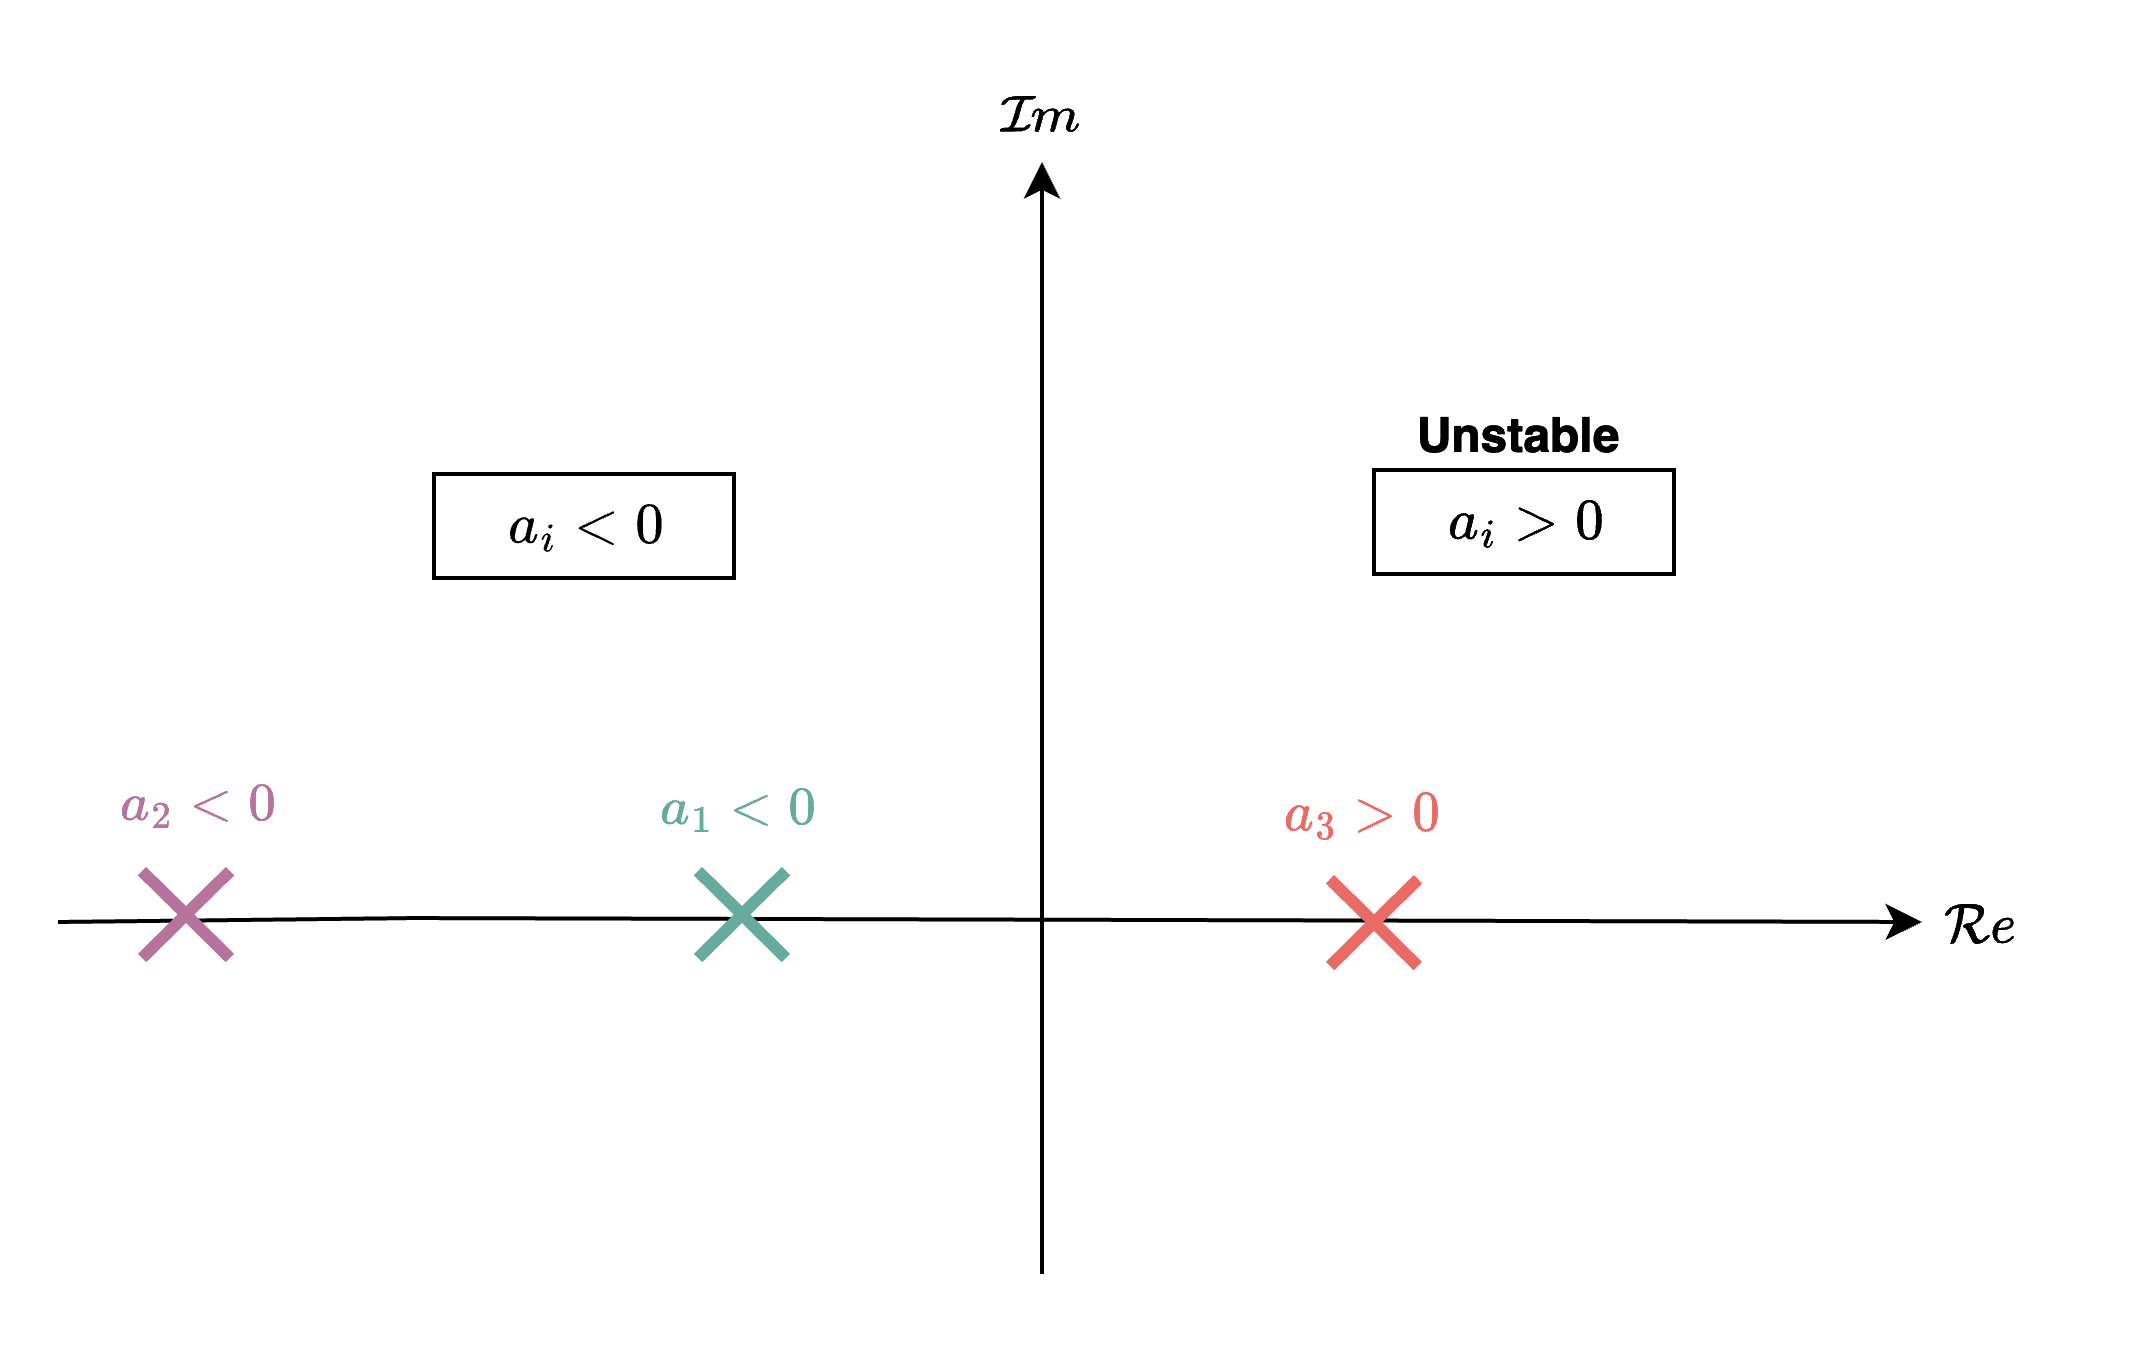

We can therefore easily check to see if a system is unstable by finding all the poles and then deducing whether any poles lie in the ORHP.

#### Example

*Determine whether *$P(s)=\frac{s+5}{s^3+s^2-s+1}$* is unstable.*

Using `MATLAB`'s `pole` function, we can check the locations of the poles of $P(s)$ as shown below.

s = tf('s');
P = (s+5)/(s^3+s^2-s+1);
p = pole(P)

p =   -1.8393 + 0.0000i
   0.4196 + 0.6063i
   0.4196 - 0.6063i


We can also use `pzmap` to plot the poles and zeros in the s-plane and then visually check to see if any poles are in the OHRP.

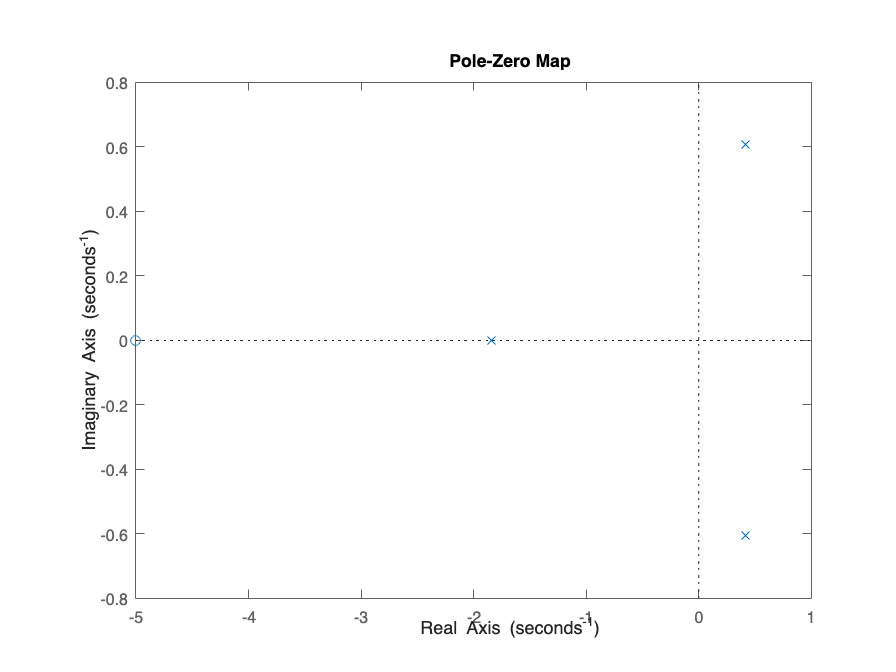

figure
pzmap(P)

Based on the above results, it is clear that two poles are in the ORHP (or $a_i>0$). Therefore $P(s)$ is classed as unstable.

### 5.7.2 Marginally stable systems

**Marginally stable** systems are those that exhibit a stable response for certain input signals, but become unstable for particular, bounded signals. We have actually already seen an example of this **Section 5.4.3**. Formally, a system will be marginally stable if a distinct pole lies on the imaginary axis. Under this condition, if an input signal contains at least one pole that matches the pole of $P(s)$ lying on the imaginary axis, then the output response is guaranteed to be unstable.

If the pole is at the origin, ie $p_1=0+j0$, then $P(s)$ is represented by


$$\begin{array}{ll}
P(s)
&=  A_p\frac{\prod_{i=1}^m (s-z_i)}{s\prod_{i=2}^n (s-p_i)}, \\
\end{array}$$


If a step input, $U(s)=\frac{1}{s}$, is now applied to the system, then the output response in the Laplace domain is


$$\begin{array}{ll}
Y(s)
&= P(s)\frac{1}{s},\\
&=  A_p\frac{\prod_{i=1}^m (s-z_i)}{s^2\prod_{i=2}^n (s-p_i)}, \\
\end{array}$$


which results in a repeated pole at $s=0$. Using our working from earlier, and assuming for sake of simplicity (without loss of generality) that the other poles are distinct, the time-domain output response can then be determined as


$$\begin{array}{rl}
y(t)
&= r_1t+\sum_{i=2}^{n}r_ie^{a_it},
\end{array}$$


where $a_i=\mathcal{R}\{p_i\}$. The first term, resulting from the two poles at $s=0$, will then run off to $\pm \infty$, depending on the sign of $r_1$. A simple example where $P(s)=\frac{1}{s}$ is shown using the code below, where an input signal of $U(s)=\frac{1}{s}$ results in an unstable response.

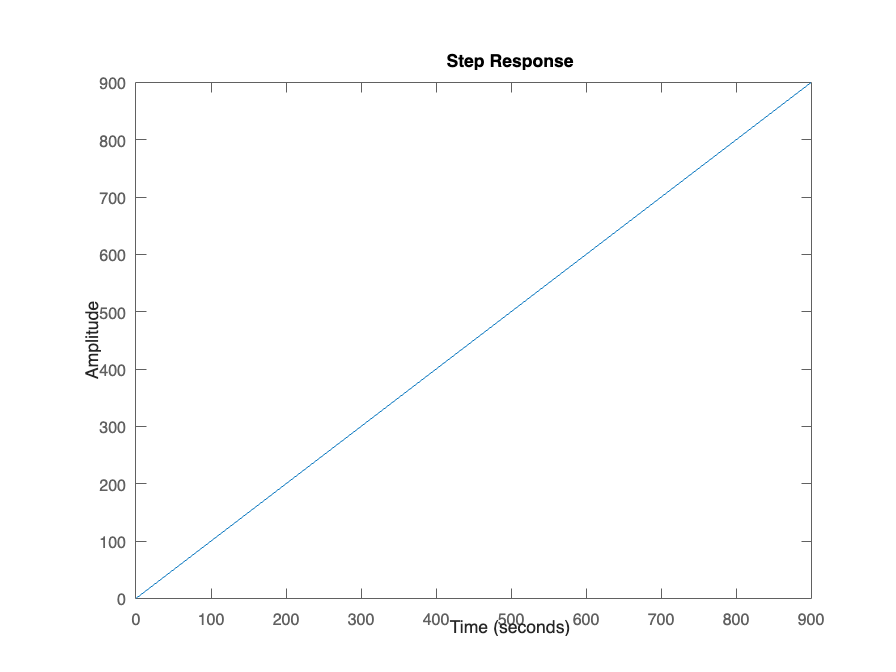

s = tf('s');
P = 1/s;
figure
step(P)

If the distinct poles lying on the imaginary axis are complex, ie $p_{1,2}=\pm jb_1$, then we can describe $P(s)$ as 


$$\begin{array}{ll}
P(s)
&=  A_p\frac{\prod_{i=1}^m (s-z_i)}{(s+jb_1)(s-jb_1)\prod_{i=3}^n (s-p_i)}, \\
\end{array}$$


If we apply an input signal that matches the frequency of the poles lying on the imaginary axis, namely $u(t)=\sin(b_1t)$, then the corresponding Laplace transform input signal is 

$U(s)=\frac{b_1}{s^2+b_1^2}=\frac{b_1}{(s+jb_1)(s-jb_1)}$.

The output response, $Y(s)=P(s)U(s)$, follows as


$$\begin{array}{ll}
Y(s)
&=  A_pb_1\frac{\prod_{i=1}^m (s-z_i)}{(s+jb_1)^2(s-jb_1)^2\prod_{i=3}^n (s-p_i)}.
\end{array}$$


It can be similary shown that the time-domain output reponse will diverge as a result of the repeated poles that lie on the imaginary axis. A simple example is shown using the code below where $P(s)=\frac{1}{s^2+b^2}$, and $u(t)=\sin(bt)$ results in an unstable response.

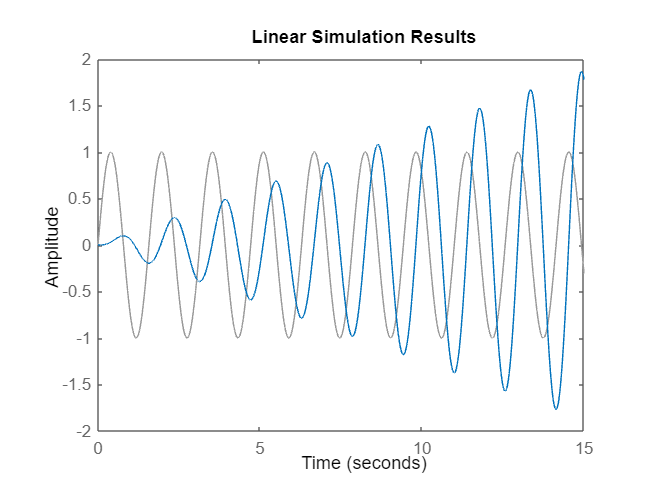

s = tf('s');

b = 4; %frequency of sinusoid and location of poles on imaginary axis
P = 1/(s^2+b^2);

t = 0:1e-3:15;
u = sin(b*t);

figure
lsim(P,u,t)

### 5.7.3 Strictly stable systems

The previous sections have shown that if any one pole in $P(s)$ lies in the ORHP or on the imaginary axis, then the output response is not guaranteed to be stable. More formally, if any one pole of $P(s)$ lies in the CRHP ($\exists a_i\geq 0$), then we cannot be sure whether the output response will be stable for all bounded inputs. Conversely, we have shown that if all poles are located in the OLHP ($a_i<0,~\forall i$), then the output response is guaranteed to be bounded if the input signal is bounded. Under this condition we can say that our system is **strictly stable**.

Equivalently, a system is classed as **bounded-input,bounded-output (BIBO) **stable if it yields a bounded output for *any* bounded input. This means that we may assess system stability using *any* arbitrary input signal, $U(s)$, with stable poles (meaning that the input is bounded). If the corresponding set of output responses are all bounded, then our system is BIBO stable. Therefore, the requirement for a system to be BIBO stable is $a_i<0, \forall i$, which is equivalent to being strictly stable.

We will refer to strictly stable (or equivalently, BIBO stable) systems from this point onwards as *stable *systems, with the implication that they meet the aforementioned conditions. The difference between a stable and unstable system is summarised in the image below.

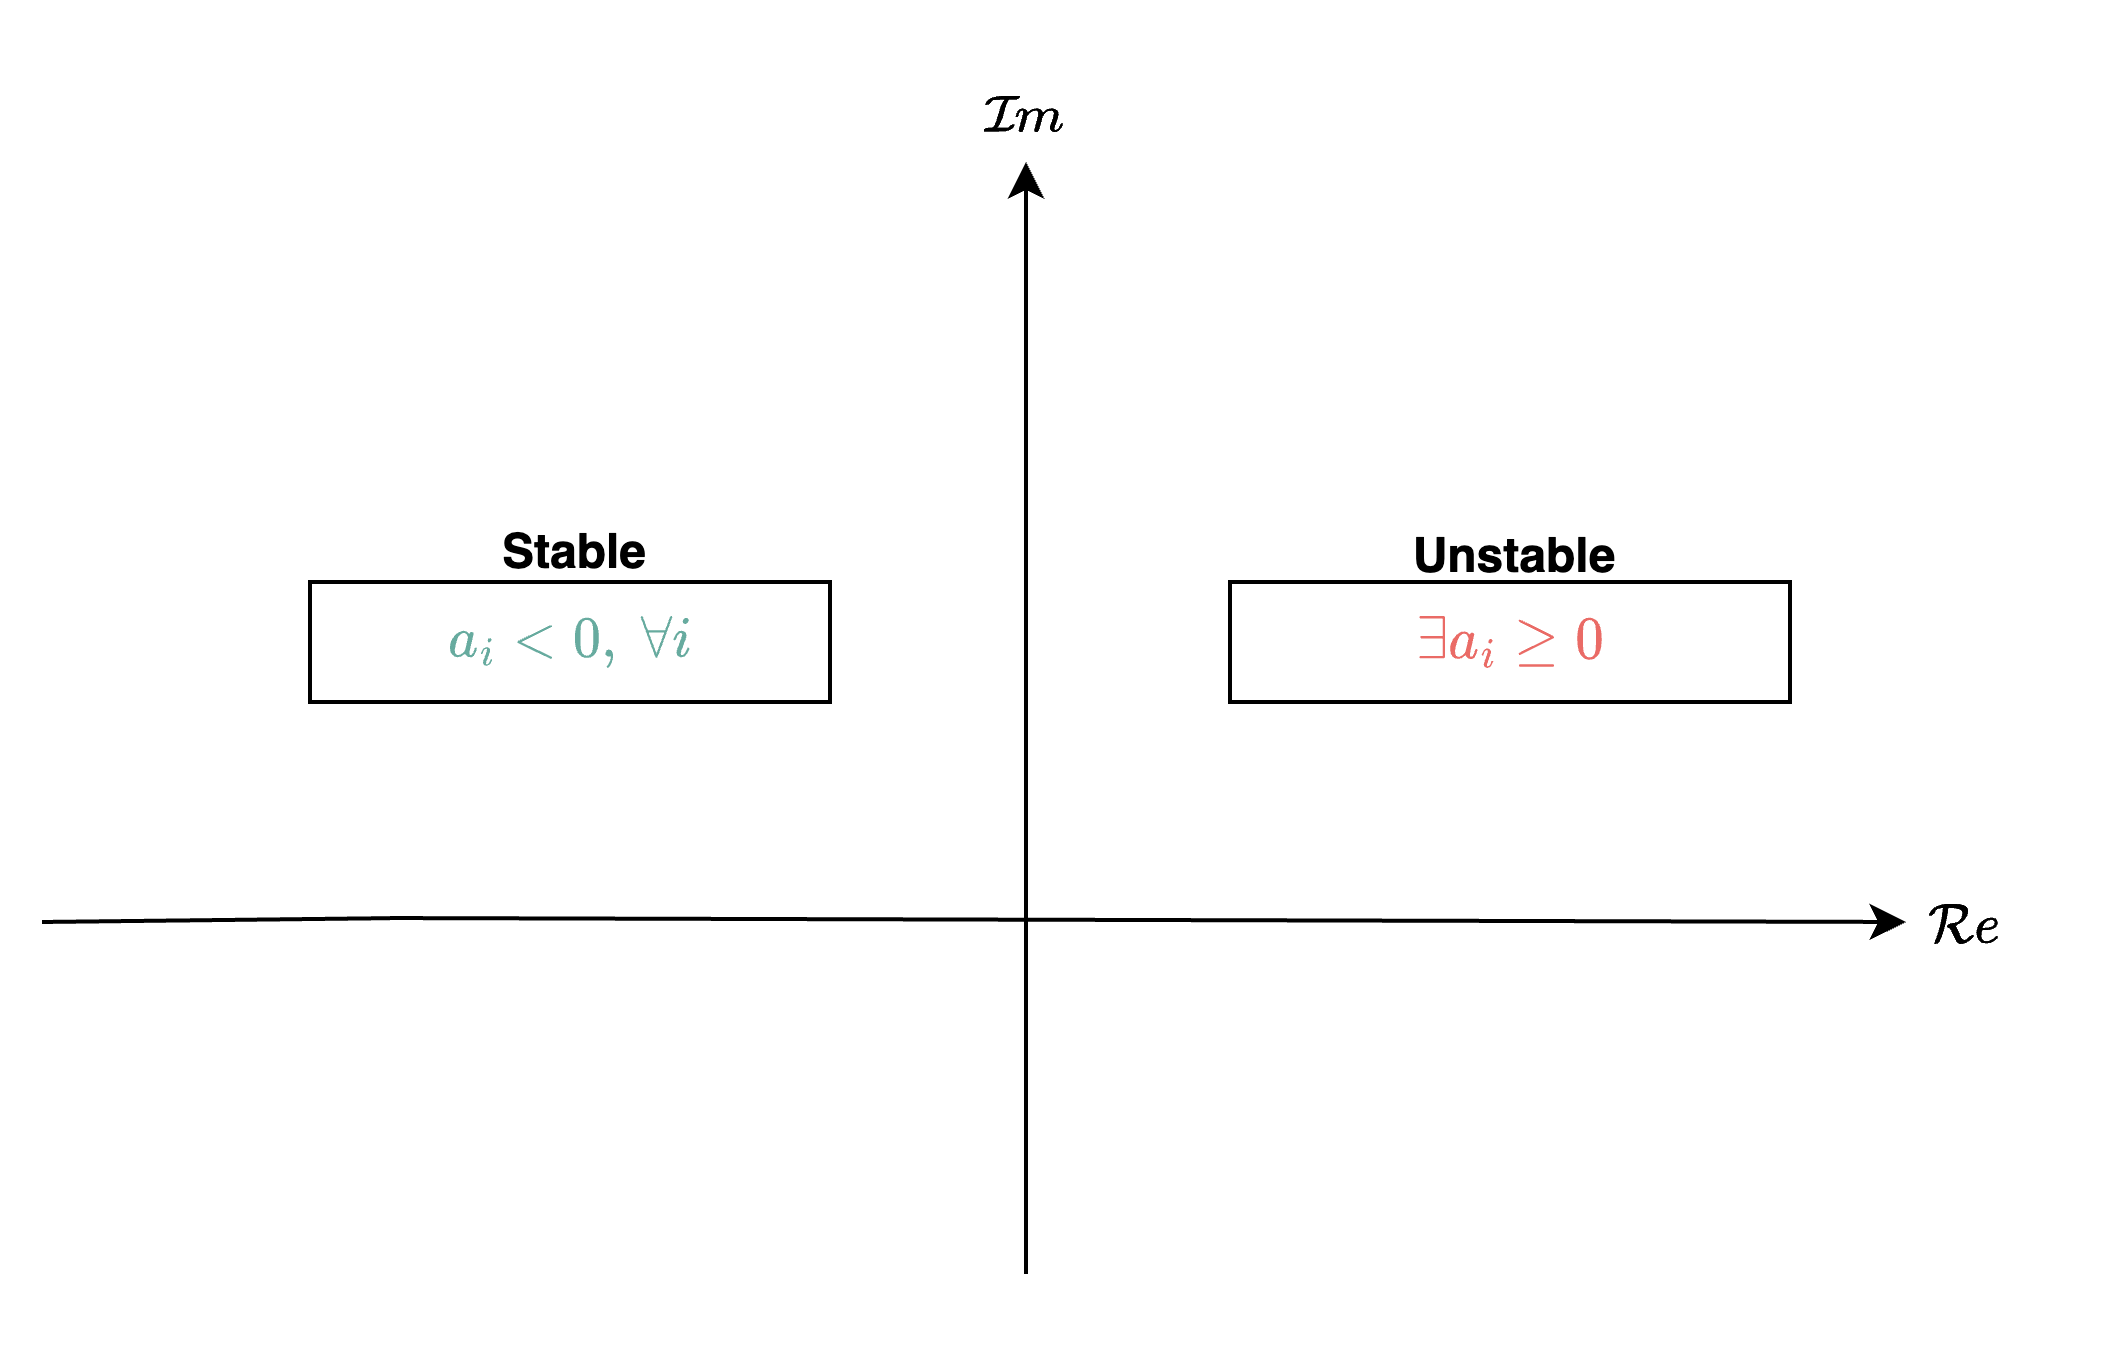

#### Example

*Determine whether *$P(s)=\frac{(s+5)^2}{s^3+2s^2+5s+1}$* is unstable.*

Using `MATLAB`'s `pole` function, we can check the locations of the poles of $P(s)$ as shown below.

s = tf('s');
P = (s+5)^2/(s^3+2*s^2+5*s+1);
p = pole(P)

p =   -0.8916 + 1.9541i
  -0.8916 - 1.9541i
  -0.2168 + 0.0000i


We can also use `pzmap` to plot the poles and zeros in the s-plane and then visually check to see if any poles are in the OHRP.

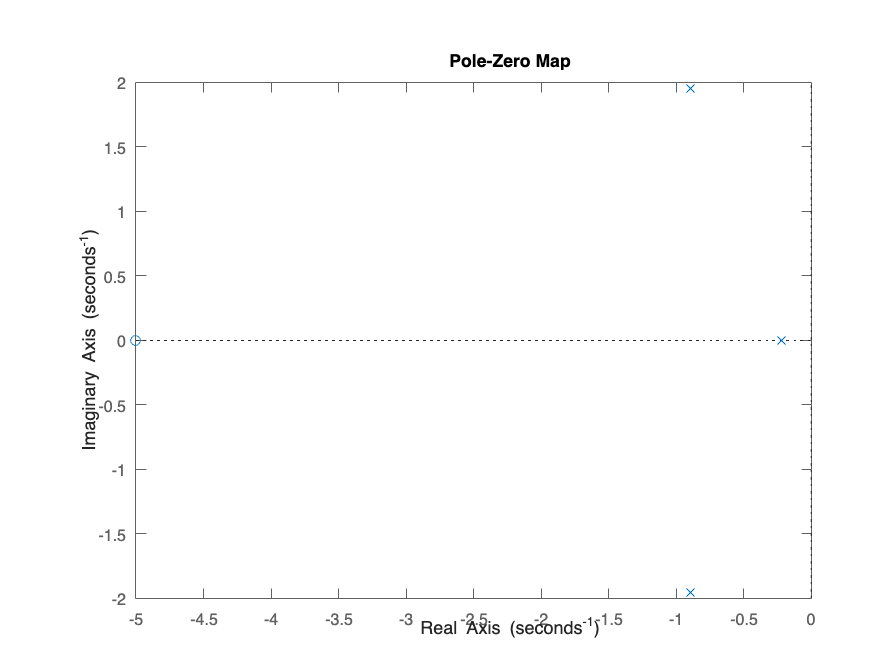

figure
pzmap(P)

Based on the above results, it is clear that all poles are in the OLHP (or $a_i<0$). Therefore $P(s)$ is classed as stable.

## 5.8 Initial and final value theorem

Initial value theorem and final value theorem are useful mathematical tools that can be used to ascertain initial and final (steady-state) behaviour of a time-domain signal, after an input signal has been applied to a system. 

### 5.8.1 Initial value theorem

**The initial value theorem (IVT)** determines the initial value of a signal, as the time parameter approaches zero: $t\rightarrow0$. In the time domain, this can be represented as

$f(0)=\lim_{t\rightarrow0}f(t)$.

We can also determine an equivalent form of the equation above that considers $F(s)$ instead of $f(t)$. This is useful if we are working in the Laplace domain (as we will tend to do in this course). 

Consider the Laplace transform of a derivative

$\mathcal{L}\{\dot{f(t)}\}=\int_{0}^\infty \dot{f}(t)e^{-st}dt=sF(s)-f(0)$.

The result above can be reorganised as

$sF(s) = \int_{0}^\infty \dot{f}(t)e^{-st}dt+f(0)$.

Taking the limit as $s\rightarrow \infty$ on both sides of the equation,


$$\begin{array}{lll}
\lim_{s\rightarrow \infty}sF(s) &= \lim_{s\rightarrow \infty}\left(\int_{0}^\infty \dot{f}(t)e^{-st}dt+f(0)\right) \\
&= f(0).
\end{array}$$


We are therefore also able to determine the initial value (value at $t=0$) of $f(t)$ using 

$f(0)=\lim_{s\rightarrow \infty}sF(s)$.

#### Example

*Use initial value theorem to determine the intial value of *$Y(s)=\frac{a}{s+b}$.

Using IVT, we obtain 

$y(0)=\lim_{s\rightarrow \infty}sY(s)=\lim_{s\rightarrow \infty}\frac{as}{s+b}=a$. 

Note that we made use of *L'Hopital's rule *to deduce the limit.

s = tf('s');

a = -10; 
b = 5; 
Y = a/(s+b);
y0 = a

y0 = -10

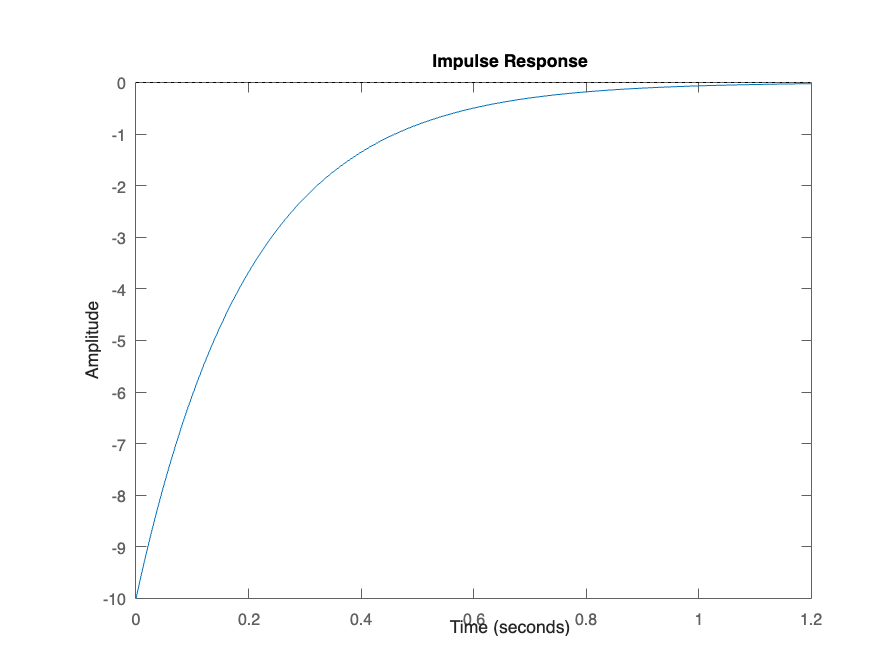


figure 
impulse(Y)

### 5.8.2 Final value theorem

The **final value theorem (FVT)** determines the steady-state value of a signal, as the time parameter tends to infinity: $t\rightarrow\infty$. In the time domain, this can be represented as

$f(\infty)=\lim_{t\rightarrow\infty}f(t)$.

We can also determine an equivalent form of the equation above that considers $F(s)$ instead of $f(t)$. The final value theorem is derived from the Laplace of a derivative

$\mathcal{L}\{\dot{f(t)}\}=\int_{0}^\infty \dot{f}(t)e^{-st}dt=sF(s)-f(0)$.

The result above can be reorganised as

$sF(s) = \int_{0}^\infty \dot{f}(t)e^{-st}dt+f(0)$.

Taking the limit as $s\rightarrow 0$ on both sides of the equation,


$$\begin{array}{lll}
\lim_{s\rightarrow 0}sF(s) &= \lim_{s\rightarrow 0}\left(\int_{0}^\infty \dot{f}(t)e^{-st}dt+f(0)\right) \\
&= \int_{0}^\infty \dot{f}(t)dt+f(0) \\
&= f(\infty).
\end{array}$$


We are therefore also able to determine the final (steady-state) value of $f(t)$ using 

$f(\infty)=\lim_{s\rightarrow 0}sF(s)$.

Note that final value theorem is only applicable to signals that are bounded (they converge to a finite value as $t\rightarrow\infty$).

#### Example

*Use final value theorem to determine the steady-state value of *$Y(s)=\frac{a}{s+b}$.

Using FVT, we obtain 

$y(\infty)=\lim_{s\rightarrow 0}sY(s)=\lim_{s\rightarrow 0}\frac{as}{s+b}=0$. 

Note that we made use of *L'Hopital's rule *to deduce the limit.

s = tf('s');

a = -10; 
b = 5; 
Y = a/(s+b);
y_inf = 0

y_inf = 0

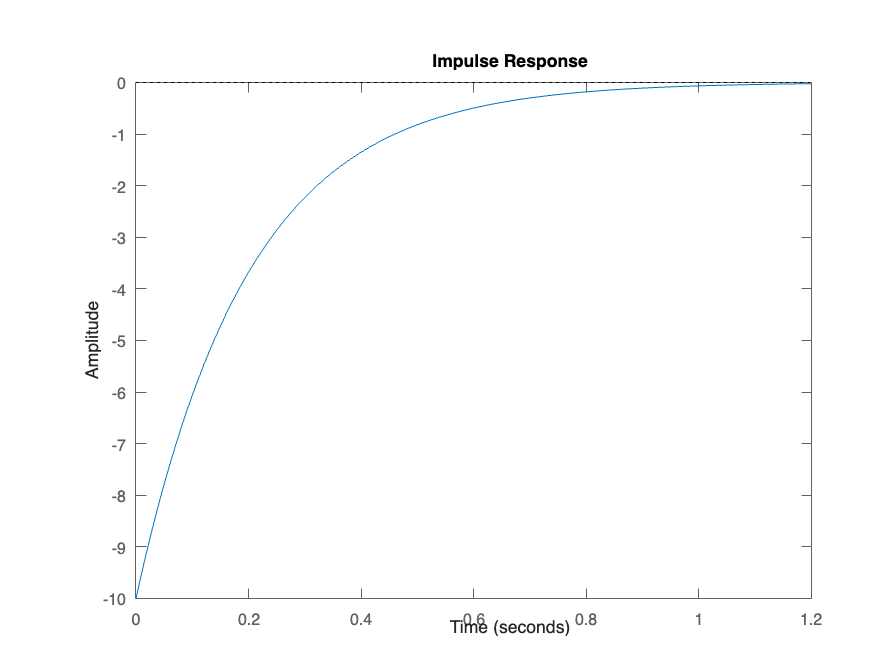


figure 
impulse(Y)